# Solar Cooling Post-processing Module

clear;
clc;

folder_name = "Mar02";
subfix_name = "02Mar";

## **Panel A (To be cooled)**

Amax_data = readtable("PanelA_" + subfix_name + "/MAXCALAF.TXT");
Amax_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'A0_temp', 'A1_temp', 'A2_temp', 'A3_temp', 'Distance_from_water_mm'}

Amax_data = 6045×14 table
    year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm
    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________

    2022      2       6      14       47        26          235.1         30.6        49.3        30.69      30.13       30.5      30.44               5           
    2


Amax_data.datetime = datetime(...
    [Amax_data.year ...
    Amax_data.month ...
    Amax_data.day ...
    Amax_data.hour ...
    Amax_data.minute ...
    Amax_data.second]);
Amax_data = movevars(Amax_data,"datetime",'Before',"year");
A_start_analyse_time = datetime(2022,2,18,0,0,0);
Amax_data_tt = table2timetable(Amax_data(Amax_data.datetime > A_start_analyse_time,:))

Amax_data_tt = 5978×14 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________

    18-Feb-2022 14:12:10    2022      2      18      14       1

Amax_data_tt.meanTemp = mean([Amax_data_tt.A0_temp Amax_data_tt.A1_temp Amax_data_tt.A2_temp Amax_data_tt.A3_temp], 2)

Amax_data_tt = 5978×15 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm    meanTemp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________    ________

    18-Feb-202


%{
figure
s = stackedplot(Amax_data_tt, {'max_power_mW', 'A0_temp', 'A1_temp', 'A2_temp', 'A3_temp', 'amb_temp', 'amb_humid'});
saveas(s, "Figures/Amax_demo_1.fig");
saveas(s, "Figures/Amax_demo_1.png");

figure
plot(Amax_data_tt.datetime, Amax_data_tt.max_power_mW)

figure
plot(Amax_data_tt.datetime, Amax_data_tt.A0_temp)
hold on
plot(Amax_data_tt.datetime, Amax_data_tt.A1_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A2_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A3_temp)
%}

## **Panel B (Reference)**

Bmax_data = readtable("PanelB_" + subfix_name + "/MAXCALBF.TXT");
Bmax_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'B0_temp', 'B1_temp', 'B2_temp', 'B3_temp'}

Bmax_data = 7409×13 table
    year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp
    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______

    2022      2       9      17       16        57            29125       34.5        51.8        40.31         40      39.75      39.38 
    2022      2       9      17       18        39            29558       33.9        52.7           40      39.63   


Bmax_data.datetime = datetime(...
    [Bmax_data.year ...
    Bmax_data.month ...
    Bmax_data.day ...
    Bmax_data.hour ...
    Bmax_data.minute ...
    Bmax_data.second]);
Bmax_data = movevars(Bmax_data,"datetime",'Before',"year");
B_start_analyse_time = datetime(2022,2,18,0,0,0);
Bmax_data_tt = table2timetable(Bmax_data(Bmax_data.datetime > B_start_analyse_time,:))

Bmax_data_tt = 7407×13 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______

    18-Feb-2022 16:14:57    2022      2      18      16       14        57       1.1302e+05       31.3        61.3           43      42.69       43.5

Bmax_data_tt.meanTemp = mean([Bmax_data_tt.B0_temp Bmax_data_tt.B1_temp Bmax_data_tt.B2_temp Bmax_data_tt.B3_temp], 2)

Bmax_data_tt = 7407×14 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp    meanTemp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ________

    18-Feb-2022 16:14:57    2022      2      18      16       14        57       1.1302e+05


%{
figure
s2 = stackedplot(Bmax_data_tt, {'max_power_mW', 'B0_temp', 'B1_temp', 'B2_temp', 'B3_temp', 'amb_temp', 'amb_humid'});
saveas(s2, "Figures/Bmax_demo_1.fig");
saveas(s2, "Figures/Bmax_demo_1.png");

figure
plot(Bmax_data_tt.datetime, Bmax_data_tt.max_power_mW)

figure
plot(Bmax_data_tt.datetime, Bmax_data_tt.B0_temp)
hold on
plot(Bmax_data_tt.datetime, Bmax_data_tt.B1_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B2_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B3_temp)
%}

## **Visualization**

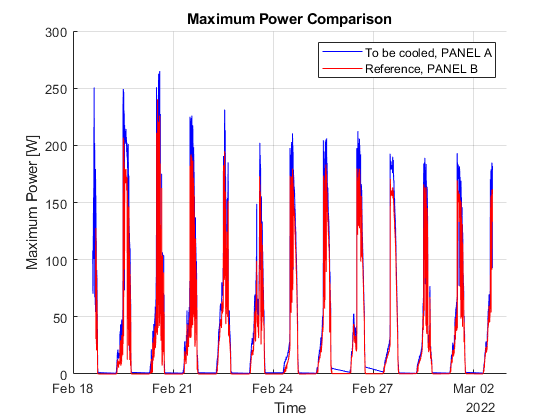

s1 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.max_power_mW./1000, 'b')
plot(Bmax_data_tt.datetime, Bmax_data_tt.max_power_mW./1000, 'r')
ylabel('Maximum Power [W]')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison')
saveas(s1, "Figures/" + folder_name + "/power_comparison.fig");
saveas(s1, "Figures/" + folder_name + "/power_comparison.png");

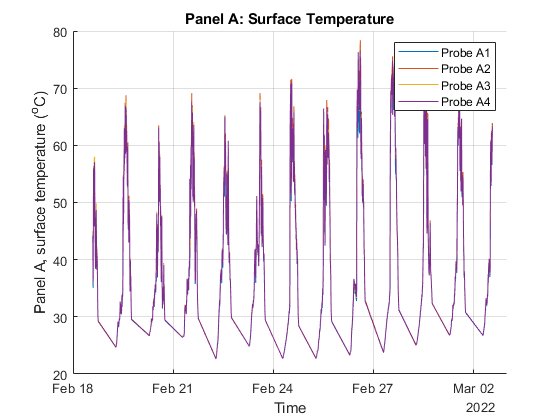


s2 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.A0_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A1_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A2_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A3_temp)
ylabel('Panel A, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4')
title('Panel A: Surface Temperature')
saveas(s2, "Figures/" + folder_name + "/Panel A surface temperature.fig");
saveas(s2, "Figures/" + folder_name + "/Panel A surface temperature.png");

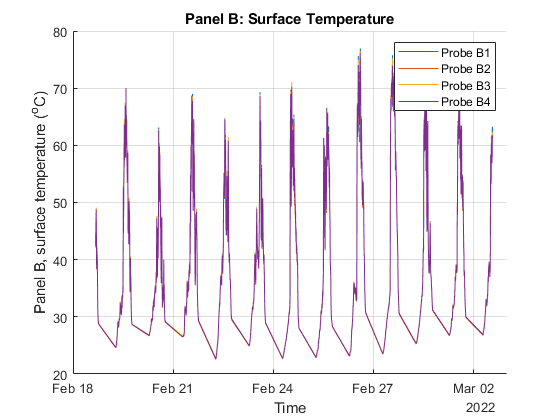

general_time_limit = get(gca, 'XLim');
general_surfaceTemp_limit = get(gca, 'YLim');

s3 = figure;
hold on
grid
plot(Bmax_data_tt.datetime, Bmax_data_tt.B0_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B1_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B2_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B3_temp)
ylabel('Panel B, surface temperature (^oC)')
xlabel('Time')
legend('Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('Panel B: Surface Temperature')
xlim(general_time_limit)
ylim(general_surfaceTemp_limit)
saveas(s3, "Figures/" + folder_name + "/Panel B surface temperature.fig");
saveas(s3, "Figures/" + folder_name + "/Panel B surface temperature.png");

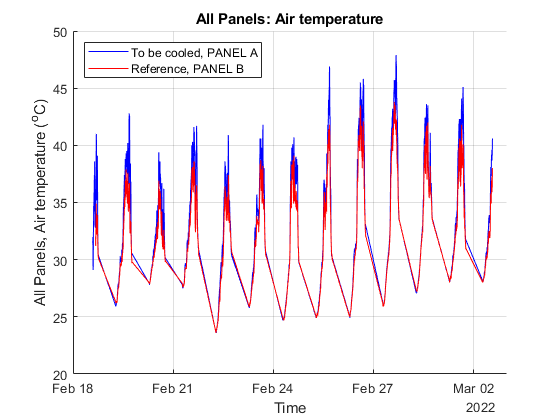


s4 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.amb_temp, 'b')
plot(Bmax_data_tt.datetime, Bmax_data_tt.amb_temp, 'r')
ylabel('All Panels, Air temperature (^oC)')
xlabel('Time')
legend({'To be cooled, PANEL A', 'Reference, PANEL B'},'Location','northwest')
title('All Panels: Air temperature')
saveas(s4, "Figures/" + folder_name + "/All air temperature.fig");
saveas(s4, "Figures/" + folder_name + "/All air temperature.png");

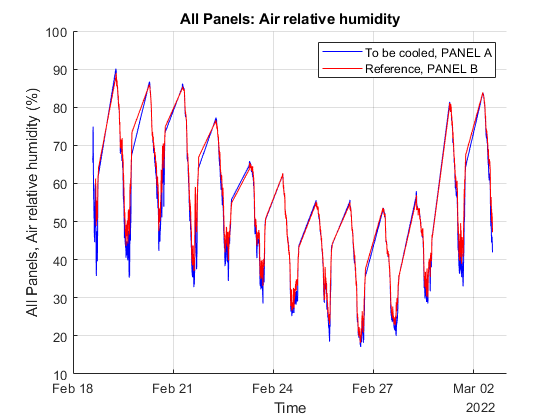


s5 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.amb_humid, 'b')
plot(Bmax_data_tt.datetime, Bmax_data_tt.amb_humid, 'r')
ylabel('All Panels, Air relative humidity (%)')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('All Panels: Air relative humidity')
saveas(s5, "Figures/" + folder_name + "/All air relative humidity.fig");
saveas(s5, "Figures/" + folder_name + "/All air relative humidity.png");

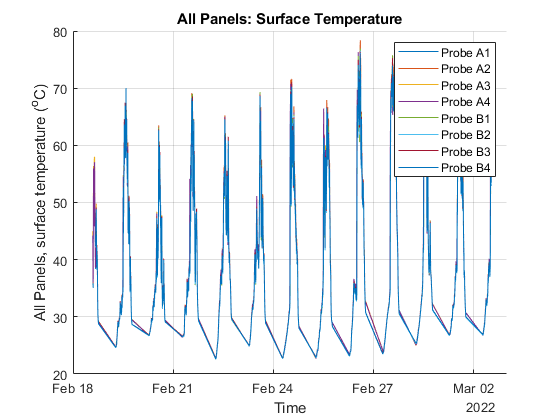



s6 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.A0_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A1_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A2_temp)
plot(Amax_data_tt.datetime, Amax_data_tt.A3_temp)

plot(Bmax_data_tt.datetime, Bmax_data_tt.B0_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B1_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B2_temp)
plot(Bmax_data_tt.datetime, Bmax_data_tt.B3_temp)
ylabel('All Panels, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4', 'Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('All Panels: Surface Temperature')
saveas(s6, "Figures/" + folder_name + "/All surface temperature.fig");
saveas(s6, "Figures/" + folder_name + "/All surface temperature.png");

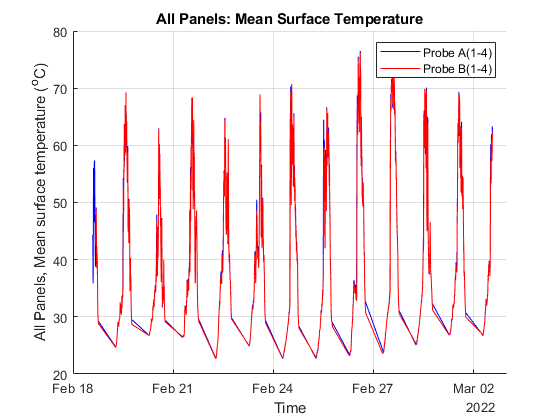



s7 = figure;
hold on
grid
plot(Amax_data_tt.datetime, Amax_data_tt.meanTemp, 'b')
plot(Bmax_data_tt.datetime, Bmax_data_tt.meanTemp, 'r')

ylabel('All Panels, Mean surface temperature (^oC)')
xlabel('Time')
legend('Probe A(1-4)', 'Probe B(1-4)')
title('All Panels: Mean Surface Temperature')
saveas(s7, "Figures/" + folder_name + "/All mean surface temperature.fig");
saveas(s7, "Figures/" + folder_name + "/All mean surface temperature.png");

## **Aggregate 10 mins**

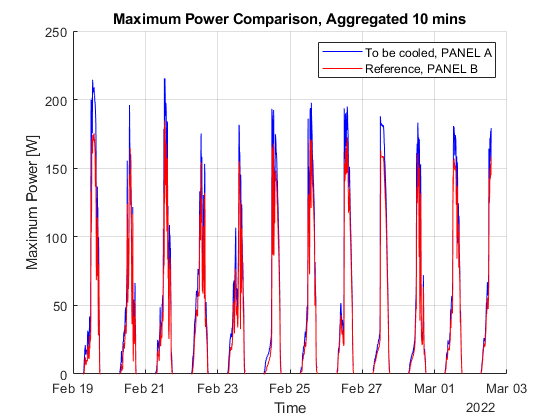

method = 'mean';
dt = minutes(10);
Amax_data_tt2 = retime(Amax_data_tt,'regular',method,'TimeStep',dt);
Bmax_data_tt2 = retime(Bmax_data_tt,'regular',method,'TimeStep',dt);

start_analyse_time = datetime(2022,2,19,0,0,0);
Amax_data_tt2 = Amax_data_tt2(Amax_data_tt2.datetime > start_analyse_time,:);
Bmax_data_tt2 = Bmax_data_tt2(Bmax_data_tt2.datetime > start_analyse_time,:);

if Amax_data_tt2.datetime(end) > Bmax_data_tt2.datetime(end)
    Amax_data_tt2 = Amax_data_tt2(Amax_data_tt2.datetime <= Bmax_data_tt2.datetime(end),:);
elseif Bmax_data_tt2.datetime(end) > Amax_data_tt2.datetime(end)
    Bmax_data_tt2 = Bmax_data_tt2(Bmax_data_tt2.datetime <= Amax_data_tt2.datetime(end),:);
end

s8 = figure;
hold on
grid
plot(Amax_data_tt2.datetime, Amax_data_tt2.max_power_mW./1000, 'b')
plot(Bmax_data_tt2.datetime, Bmax_data_tt2.max_power_mW./1000, 'r')
ylabel('Maximum Power [W]')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison, Aggregated 10 mins')
saveas(s8, "Figures/" + folder_name + "/power_comparison_resampling10mins.fig");
saveas(s8, "Figures/" + folder_name + "/power_comparison_resampling10mins.png");

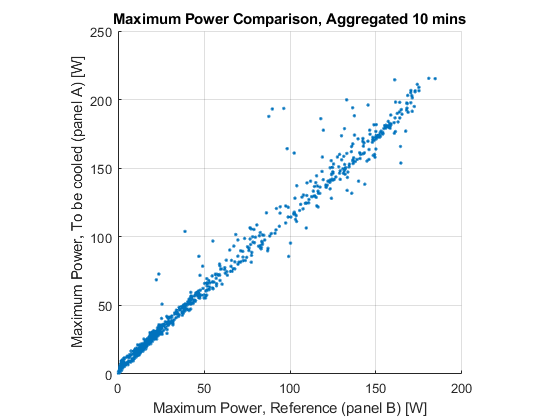


joined_tt = join(Amax_data_tt2, Bmax_data_tt2, 'Keys', 'datetime');

s9 = figure;
hold on
grid
plot(joined_tt.max_power_mW_Bmax_data_tt2./1000, ...
    joined_tt.max_power_mW_Amax_data_tt2./1000, '.')
ylabel('Maximum Power, To be cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
%legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison, Aggregated 10 mins')
axis square
%power_limit = get(gca, 'YLim');
%xlim(power_limit)

saveas(s9, "Figures/" + folder_name + "/power_comparison_resampling10mins_xy.fig");
saveas(s9, "Figures/" + folder_name + "/power_comparison_resampling10mins_xy.png");

## **Linear model fitting**

joined_tt_clean = joined_tt(~any(ismissing(joined_tt),2),:);
joined_tt_clean.day = datestr(joined_tt_clean.datetime,'dddd');

max_mW_A = joined_tt_clean.max_power_mW_Amax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 2000.0);
max_mW_B = joined_tt_clean.max_power_mW_Bmax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 2000.0);
meanTemp_A = joined_tt_clean.meanTemp_Amax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 2000.0);
meanTemp_B = joined_tt_clean.meanTemp_Bmax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 2000.0);
day_list = joined_tt_clean.day(joined_tt_clean.max_power_mW_Bmax_data_tt2 > 2000.0, :);

keySet = {'Saturday ','Friday   ','Thursday ','Wednesday','Tuesday  ','Monday   ','Sunday   '};
valueSet = [0 1 2 3 4 5 6];
M = containers.Map(keySet, valueSet)

M =   Map with properties:

        Count: 7
      KeyType: char
    ValueType: double


day_mapped = zeros(height(day_list), 1);
for i = 1:height(day_list)
    day_mapped(i) = M(day_list(i,:));
end

mdl = fitlm(max_mW_B, max_mW_A)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     5307.5        560.89    9.4626    4.3621e-20
    x1              1.1296     0.0066715    169.31             0


Number of observations: 709, Error degrees of freedom: 707
Root Mean Squared Error: 9.55e+03
R-squared: 0.976,  Adjusted R-Squared: 0.976
F-statistic vs. constant model: 2.87e+04, p-value = 0

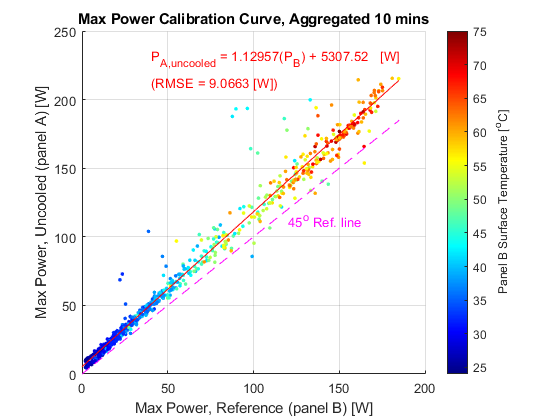

Apred = predict(mdl,joined_tt_clean.max_power_mW_Bmax_data_tt2);
rmse_cal = sqrt(mean((joined_tt_clean.max_power_mW_Amax_data_tt2 - Apred).^2))/1000;

s10 = figure;
hold on
grid
max_temp = max(max(meanTemp_A), max(meanTemp_B));
min_temp = min(min(meanTemp_A), min(meanTemp_B));

scatter(max_mW_B./1000, max_mW_A./1000, 8, meanTemp_B,'filled')
colorbar
colormap jet
h = colorbar;
ylabel(h, 'Panel B Surface Temperature [^oC]')
plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, Apred./1000, '-r')
ylabel('Max Power, Uncooled (panel A) [W]')
xlabel('Max Power, Reference (panel B) [W]')
title('Max Power Calibration Curve, Aggregated 10 mins')
axis square
xl = xlim;
yl = ylim;
xt = 0.20 * (xl(2)-xl(1)) + xl(1);
yt = 0.92 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('P_A_,_u_n_c_o_o_l_e_d = %1.5f(P_B) + %4.2f   [W]', mdl.Coefficients.Estimate(2), abs(mdl.Coefficients.Estimate(1)));
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');

xt = 0.20 * (xl(2)-xl(1)) + xl(1);
yt = 0.85 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('(RMSE = %2.4f [W])', rmse_cal);
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');

plot(0:5:185, 0:5:185, '--m')
xt = 0.60 * (xl(2)-xl(1)) + xl(1);
yt = 0.45 * (yl(2)-yl(1)) + yl(1);
caption = "45^o Ref. line";
text(xt, yt, caption, 'FontSize', 10, 'Color', 'm');

saveas(s10, "Figures/" + folder_name + "/power_comparison_10calCurve2.fig");
saveas(s10, "Figures/" + folder_name + "/power_comparison_10calCurve2.png");

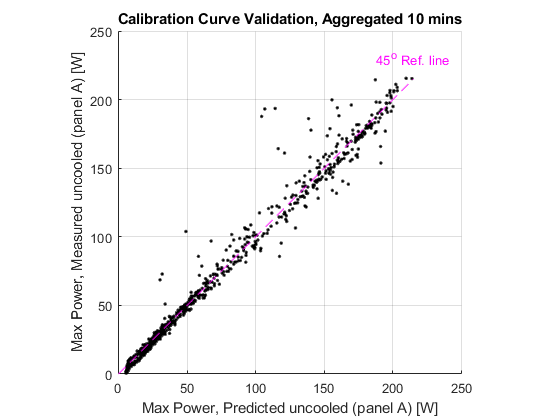

s10v = figure;
hold on
grid

plot(Apred./1000, joined_tt_clean.max_power_mW_Amax_data_tt2./1000, '.k')
plot(0:5:215, 0:5:215, '--m')
ylabel('Max Power, Measured uncooled (panel A) [W]')
xlabel('Max Power, Predicted uncooled (panel A) [W]')
title('Calibration Curve Validation, Aggregated 10 mins')
axis square
xl = xlim;
yl = ylim;
xt = 0.75 * (xl(2)-xl(1)) + xl(1);
yt = 0.92 * (yl(2)-yl(1)) + yl(1);
caption = "45^o Ref. line";
text(xt, yt, caption, 'FontSize', 10, 'Color', 'm');

saveas(s10v, "Figures/" + folder_name + "/calibrating_validation1.fig");
saveas(s10v, "Figures/" + folder_name + "/calibrating_validation1.png");

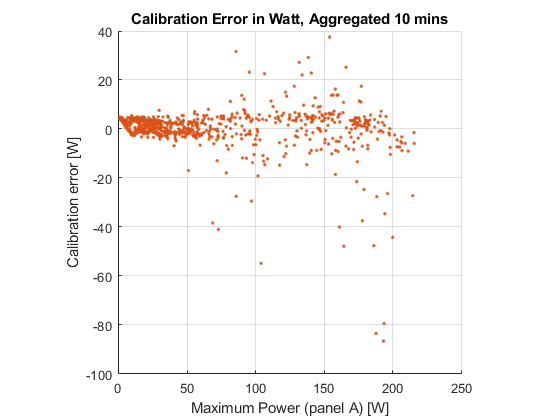

cal_error = (Apred - joined_tt_clean.max_power_mW_Amax_data_tt2)./1000;

s10v2 = figure;
hold on
grid
axis square
plot(joined_tt_clean.max_power_mW_Amax_data_tt2./1000, cal_error, '.', 'Color', [0.8500 0.3250 0.0980])
ylabel('Calibration error [W]')
xlabel('Maximum Power (panel A) [W]')
%legend({'Measured', 'Predicted'},'Location','northwest')
title('Calibration Error in Watt, Aggregated 10 mins')
saveas(s10v2, "Figures/" + folder_name + "/calibrating_validation2.fig");
saveas(s10v2, "Figures/" + folder_name + "/calibrating_validation2.png");

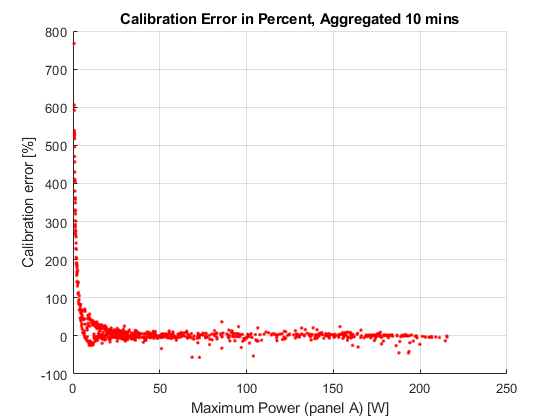

cal_error_percent = ((Apred - joined_tt_clean.max_power_mW_Amax_data_tt2)./joined_tt_clean.max_power_mW_Amax_data_tt2) * 100;

s10v3 = figure;
hold on
grid
%axis square
plot(joined_tt_clean.max_power_mW_Amax_data_tt2./1000, cal_error_percent, '.r')
ylabel('Calibration error [%]')
xlabel('Maximum Power (panel A) [W]')
%legend({'Measured', 'Predicted'},'Location','northwest')
title('Calibration Error in Percent, Aggregated 10 mins')
saveas(s10v3, "Figures/" + folder_name + "/calibrating_validation3.fig");
saveas(s10v3, "Figures/" + folder_name + "/calibrating_validation3.png");

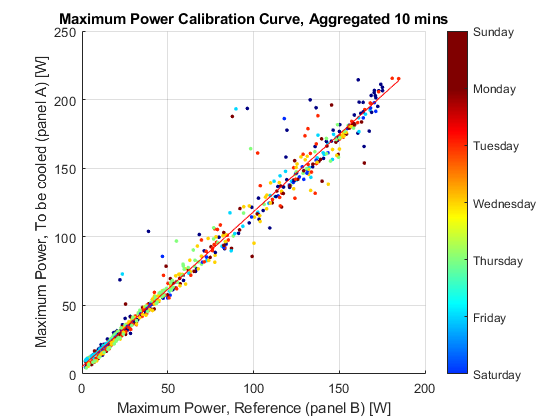

sA10 = figure;
hold on
grid
scatter(max_mW_B./1000, max_mW_A./1000, 8, day_mapped(:),'filled')
colorbar
colormap jet

labels = {'Saturday','Friday','Thursday','Wednesday','Tuesday','Monday','Sunday'}; % explicitly indicate the labels
h2 = colorbar('Ticks', 1:7, 'TickLabels', labels, 'limits', [1 7]);

%plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, joined_tt_clean.max_power_mW_Amax_data_tt2./1000, '.')
%plot(max_mW_B./1000, max_mW_A./1000, '.')
plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, Apred./1000, '-r')
ylabel('Maximum Power, To be cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
%legend({'Measured', 'Predicted'},'Location','northwest')
title('Maximum Power Calibration Curve, Aggregated 10 mins')
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(sA10, "Figures/" + folder_name + "/power_comparison_10calCurve_byDays.fig");
saveas(sA10, "Figures/" + folder_name + "/power_comparison_10calCurve_byDays.png");

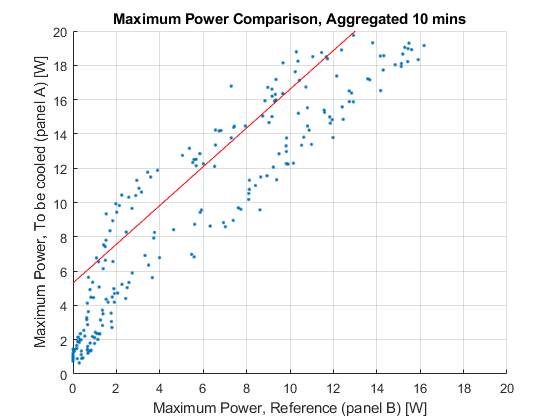

sB9 = figure;
hold on
grid
plot(joined_tt.max_power_mW_Bmax_data_tt2./1000, ...
    joined_tt.max_power_mW_Amax_data_tt2./1000, '.')
plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, Apred./1000, '-r')
ylabel('Maximum Power, To be cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
%legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison, Aggregated 10 mins')
%power_limit = get(gca, 'YLim');
xlim([0 20])
ylim([0 20])
set(gca,'xtick',[0:2:20])
set(gca,'ytick',[0:2:20])

saveas(sB9, "Figures/" + folder_name + "/power_comparison_10calCurve3.fig");
saveas(sB9, "Figures/" + folder_name + "/power_comparison_10calCurve3.png");

sC10 = figure;
hold on
grid
% max_power = max(max(max_mW_A), max(max_mW_B));
% min_power = min(min(max_mW_A), min(max_mW_B));
meanTemp_A_full = joined_tt_clean.meanTemp_Amax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 0.0);
meanTemp_B_full = joined_tt_clean.meanTemp_Bmax_data_tt2(joined_tt_clean.max_power_mW_Bmax_data_tt2 >= 0.0);

mdl_temp = fitlm(meanTemp_B_full, meanTemp_A_full)

mdl_temp = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue 
                   ________    _________    _______    _______

    (Intercept)    -0.14652      0.14162    -1.0346    0.30117
    x1               1.0138    0.0032803     309.07          0


Number of observations: 799, Error degrees of freedom: 797
Root Mean Squared Error: 1.24
R-squared: 0.992,  Adjusted R-Squared: 0.992
F-statistic vs. constant model: 9.55e+04, p-value = 0

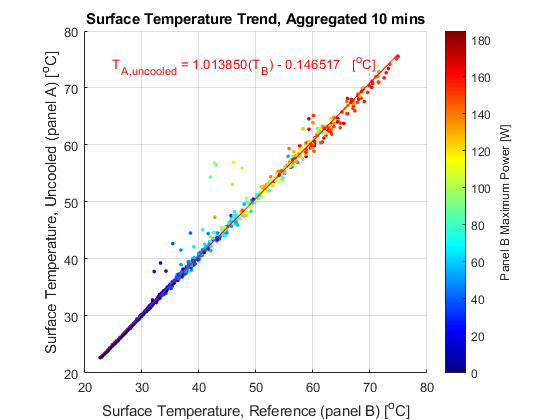

%lm = fitlm(joined_tt_clean,'max_power_mW_Amax_data_tt2~max_power_mW_Bmax_data_tt2')

Apred_temp = predict(mdl_temp, meanTemp_B_full);

scatter(meanTemp_B_full, meanTemp_A_full, 8, joined_tt_clean.max_power_mW_Bmax_data_tt2./1000,'filled')
colorbar
colormap jet
h3 = colorbar;
plot(meanTemp_B_full, Apred_temp, '-r')
xl = xlim;
yl = ylim;
xt = 0.08 * (xl(2)-xl(1)) + xl(1);
yt = 0.90 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('T_A_,_u_n_c_o_o_l_e_d = %f(T_B) - %f   [^oC]', mdl_temp.Coefficients.Estimate(2), abs(mdl_temp.Coefficients.Estimate(1)));
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');
ylabel(h3, 'Panel B Maximum Power [W]')
ylabel('Surface Temperature, Uncooled (panel A) [^oC]')
xlabel('Surface Temperature, Reference (panel B) [^oC]')
%legend({'Measured', 'Predicted'},'Location','northwest')
title('Surface Temperature Trend, Aggregated 10 mins')
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(sC10, "Figures/" + folder_name + "/temperature_trend.fig");
saveas(sC10, "Figures/" + folder_name + "/temperature_trend.png");

# Power referencing

%{
% this no longer needed; Clothes are function after 30 Mar
folder_name2 = "Mar30";
subfix_name2 = "30Mar";

## Panel A (Cooled)

A2max_data = readtable("PanelA_" + subfix_name2 + "/MAXCALAF.TXT");
A2max_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'A0_temp', 'A1_temp', 'A2_temp', 'A3_temp', 'Distance_from_water_mm'}

A2max_data.datetime = datetime(...
    [A2max_data.year ...
    A2max_data.month ...
    A2max_data.day ...
    A2max_data.hour ...
    A2max_data.minute ...
    A2max_data.second]);
A2max_data = movevars(A2max_data,"datetime",'Before',"year");
A2_start_analyse_time = datetime(2022,3,5,0,0,0); % Finished setup on 05 March
A2max_data_tt = table2timetable(A2max_data(A2max_data.datetime > A2_start_analyse_time,:))
A2max_data_tt.meanTemp = mean([A2max_data_tt.A0_temp A2max_data_tt.A1_temp A2max_data_tt.A2_temp A2max_data_tt.A3_temp], 2)

## Panel B (Reference)

B2max_data = readtable("PanelB_" + subfix_name2 + "/MAXCALBF.TXT");
B2max_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'B0_temp', 'B1_temp', 'B2_temp', 'B3_temp'}

B2max_data.datetime = datetime(...
    [B2max_data.year ...
    B2max_data.month ...
    B2max_data.day ...
    B2max_data.hour ...
    B2max_data.minute ...
    B2max_data.second]);
B2max_data = movevars(B2max_data,"datetime",'Before',"year");
B2_start_analyse_time = datetime(2022,3,5,0,0,0); % Finished setup on 05 March
B2max_data_tt = table2timetable(B2max_data(B2max_data.datetime > B2_start_analyse_time,:))
B2max_data_tt.meanTemp = mean([B2max_data_tt.B0_temp B2max_data_tt.B1_temp B2max_data_tt.B2_temp B2max_data_tt.B3_temp], 2)

## **Visualization**

s11 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.max_power_mW./1000, 'b')
plot(B2max_data_tt.datetime, B2max_data_tt.max_power_mW./1000, 'r')
ylabel('Maximum Power [W]')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison')
saveas(s11, "Figures/" + folder_name2 + "/power_comparison.fig");
saveas(s11, "Figures/" + folder_name2 + "/power_comparison.png");

s12 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.A0_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A1_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A2_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A3_temp)
ylabel('Panel A, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4')
title('Panel A: Surface Temperature')
saveas(s12, "Figures/" + folder_name2 + "/Panel A surface temperature.fig");
saveas(s12, "Figures/" + folder_name2 + "/Panel A surface temperature.png");
general_time_limit = get(gca, 'XLim');
general_surfaceTemp_limit = get(gca, 'YLim');

s13 = figure;
hold on
grid
plot(B2max_data_tt.datetime, B2max_data_tt.B0_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B1_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B2_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B3_temp)
ylabel('Panel B, surface temperature (^oC)')
xlabel('Time')
legend('Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('Panel B: Surface Temperature')
xlim(general_time_limit)
ylim(general_surfaceTemp_limit)
saveas(s13, "Figures/" + folder_name2 + "/Panel B surface temperature.fig");
saveas(s13, "Figures/" + folder_name2 + "/Panel B surface temperature.png");

s14 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.amb_temp, 'b')
plot(B2max_data_tt.datetime, B2max_data_tt.amb_temp, 'r')
ylabel('All Panels, Air temperature (^oC)')
xlabel('Time')
legend({'To be cooled, PANEL A', 'Reference, PANEL B'},'Location','northwest')
title('All Panels: Air temperature')
saveas(s14, "Figures/" + folder_name2 + "/All air temperature.fig");
saveas(s14, "Figures/" + folder_name2 + "/All air temperature.png");

s15 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.amb_humid, 'b')
plot(B2max_data_tt.datetime, B2max_data_tt.amb_humid, 'r')
ylabel('All Panels, Air relative humidity (%)')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('All Panels: Air relative humidity')
saveas(s15, "Figures/" + folder_name2 + "/All air relative humidity.fig");
saveas(s15, "Figures/" + folder_name2 + "/All air relative humidity.png");


s16 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.A0_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A1_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A2_temp)
plot(A2max_data_tt.datetime, A2max_data_tt.A3_temp)

plot(B2max_data_tt.datetime, B2max_data_tt.B0_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B1_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B2_temp)
plot(B2max_data_tt.datetime, B2max_data_tt.B3_temp)
ylabel('All Panels, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4', 'Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('All Panels: Surface Temperature')
saveas(s16, "Figures/" + folder_name2 + "/All surface temperature.fig");
saveas(s16, "Figures/" + folder_name2 + "/All surface temperature.png");


s17 = figure;
hold on
grid
plot(A2max_data_tt.datetime, A2max_data_tt.meanTemp, 'b')
plot(B2max_data_tt.datetime, B2max_data_tt.meanTemp, 'r')

ylabel('All Panels, Mean surface temperature (^oC)')
xlabel('Time')
legend('Probe A(1-4)', 'Probe B(1-4)')
title('All Panels: Mean Surface Temperature')
saveas(s17, "Figures/" + folder_name2 + "/All mean surface temperature.fig");
saveas(s17, "Figures/" + folder_name2 + "/All mean surface temperature.png");

## Aggregate (mean) 10 Mins

method2 = 'mean';
dt2 = minutes(10);
A2max_data_tt2 = retime(A2max_data_tt,'regular',method2,'TimeStep',dt2);
B2max_data_tt2 = retime(B2max_data_tt,'regular',method2,'TimeStep',dt2);

start_analyse_time2 = datetime(2022,3,5,0,0,0);
A2max_data_tt2 = A2max_data_tt2(A2max_data_tt2.datetime > start_analyse_time2,:);
B2max_data_tt2 = B2max_data_tt2(B2max_data_tt2.datetime > start_analyse_time2,:);

if A2max_data_tt2.datetime(end) > B2max_data_tt2.datetime(end)
    A2max_data_tt2 = A2max_data_tt2(A2max_data_tt2.datetime <= B2max_data_tt2.datetime(end),:);
elseif B2max_data_tt2.datetime(end) > A2max_data_tt2.datetime(end)
    B2max_data_tt2 = B2max_data_tt2(B2max_data_tt2.datetime <= A2max_data_tt2.datetime(end),:);
end

joined_tt2 = join(A2max_data_tt2, B2max_data_tt2, 'Keys', 'datetime');
joined_tt2_clean = joined_tt2(~any(ismissing(joined_tt2),2),:);

## Prediction

max_mW_A2 = joined_tt2_clean.max_power_mW_A2max_data_tt2(joined_tt2_clean.max_power_mW_B2max_data_tt2 > 2000.0);
max_mW_B2 = joined_tt2_clean.max_power_mW_B2max_data_tt2(joined_tt2_clean.max_power_mW_B2max_data_tt2 > 2000.0);

mdl2 = fitlm(max_mW_B2, max_mW_A2)
%lm2 = fitlm(joined_tt_clean,'max_power_mW_Amax_data_tt2~max_power_mW_Bmax_data_tt2')

A2pred = predict(mdl2,joined_tt2_clean.max_power_mW_B2max_data_tt2);
A2pred_with_refModel = predict(mdl,joined_tt2_clean.max_power_mW_B2max_data_tt2);
A_diff = A2pred - A2pred_with_refModel;

s18 = figure;
hold on
grid
%plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, joined_tt_clean.max_power_mW_Amax_data_tt2./1000, '.')
plot(max_mW_B2./1000, max_mW_A2./1000, '.', 'Color', [0.9290 0.6940 0.1250])
plot(joined_tt2_clean.max_power_mW_B2max_data_tt2./1000, A2pred./1000, '-r')
ylabel('Maximum Power, To be cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Measured', 'Fitted'},'Location','northwest')
title('Maximum Power Curve Fitting, Aggregated 10 mins')
% set(gca,'xtick',[0:25:200])
% set(gca,'ytick',[0:25:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(s18, "Figures/" + folder_name2 + "/power_comparison_10calCurve.fig");
saveas(s18, "Figures/" + folder_name2 + "/power_comparison_10calCurve.png");

s19 = figure;
hold on
grid
plot(max_mW_B./1000, max_mW_A./1000, '.')
plot(max_mW_B2./1000, max_mW_A2./1000, '.', 'Color', [0.9290 0.6940 0.1250])
plot(joined_tt2_clean.max_power_mW_B2max_data_tt2./1000, A2pred./1000, '-r')
plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, Apred./1000, '-b')
ylabel('Maximum Power, Uncooled/Cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Uncooled-Measured', 'Uncooled-Predicted', 'Cooled-Measured', 'Cooled-Fitted'},'Location','northwest')
title('Power trend Comparison, Aggregated 10 mins')
% set(gca,'xtick',[0:10:200])
% set(gca,'ytick',[0:25:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(s19, "Figures/" + folder_name2 + "/calCurve_compare.fig");
saveas(s19, "Figures/" + folder_name2 + "/calCurve_compare.png");

s20 = figure;
hold on
grid
%plot(max_mW_B./1000, max_mW_A./1000, '.')
plot(max_mW_B2./1000, max_mW_A2./1000, '.', 'Color', [0.9290 0.6940 0.1250])
plot(joined_tt2_clean.max_power_mW_B2max_data_tt2./1000, A2pred./1000, '-r')
plot(joined_tt2_clean.max_power_mW_B2max_data_tt2./1000, A2pred_with_refModel./1000, '-b')
ylabel('Maximum Power, Uncooled/Cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Uncooled-Predicted', 'Cooled-Measured', 'Cooled-Fitted'},'Location','northwest')
title('Power trend Comparison (10Min-meanAggregated)')
% set(gca,'xtick',[0:20:200])
% set(gca,'ytick',[0:20:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(s20, "Figures/" + folder_name2 + "/predictCalCurve.fig");
saveas(s20, "Figures/" + folder_name2 + "/predictCalCurve.png");

s21 = figure;
hold on
grid
% max_power = max(max(max_mW_A), max(max_mW_B));
% min_power = min(min(max_mW_A), min(max_mW_B));
meanTemp_A2_full = joined_tt2_clean.meanTemp_A2max_data_tt2(joined_tt2_clean.max_power_mW_B2max_data_tt2 >= 0.0);
meanTemp_B2_full = joined_tt2_clean.meanTemp_B2max_data_tt2(joined_tt2_clean.max_power_mW_B2max_data_tt2 >= 0.0);

%mdl_temp = fitlm(meanTemp_B_full, meanTemp_A_full)
%lm = fitlm(joined_tt_clean,'max_power_mW_Amax_data_tt2~max_power_mW_Bmax_data_tt2')

A2pred_temp = predict(mdl_temp, meanTemp_B2_full);

scatter(meanTemp_B2_full, meanTemp_A2_full, 8, joined_tt2_clean.max_power_mW_B2max_data_tt2./1000,'filled')
colorbar
colormap jet
h3 = colorbar;
plot(meanTemp_B2_full, A2pred_temp, '-r')
xl = xlim;
yl = ylim;
xt = 0.15 * (xl(2)-xl(1)) + xl(1);
yt = 0.90 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('T_A = %f(T_B) - %f   [^oC]', mdl_temp.Coefficients.Estimate(2), abs(mdl_temp.Coefficients.Estimate(1)));
text(xt, yt, caption, 'FontSize', 12, 'Color', 'k');
ylabel(h3, 'Panel B Maximum Power [W]')
ylabel('Surface Temperature, To be cooled (panel A) [^oC]')
xlabel('Surface Temperature, Reference (panel B) [^oC]')
%legend({'Measured', 'Predicted'},'Location','northwest')
title('Surface Temperature, Aggregated 10 mins')
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
saveas(s21, "Figures/" + folder_name2 + "/temperature_trend.fig");
saveas(s21, "Figures/" + folder_name2 + "/temperature_trend.png");
%}

## Continue with Lux meter

folder_name3 = "Apr18";
subfix_name3 = "18Apr";

## Panel A (Cooled)

A3max_data = readtable("PanelA_" + subfix_name3 + "/MAXCALAA.TXT");
A3max_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'A0_temp', 'A1_temp', 'A2_temp', 'A3_temp', 'Distance_from_water_mm', 'Lux'}

A3max_data = 9210×15 table
    year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm    Lux
    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________    ___

    2022      3      30      15        2        29       1.6617e+05       41.7        33.4        70.88      73.25      


A3max_data.datetime = datetime(...
    [A3max_data.year ...
    A3max_data.month ...
    A3max_data.day ...
    A3max_data.hour ...
    A3max_data.minute ...
    A3max_data.second]);
A3max_data = movevars(A3max_data,"datetime",'Before',"year");
A3_start_analyse_time = datetime(2022,3,31,0,0,0); % Update Lux data structure on 31 Mar
A3max_data_tt = table2timetable(A3max_data(A3max_data.datetime > A3_start_analyse_time,:))

A3max_data_tt = 9061×15 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm    Lux
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________    ___

    31-Mar-2022 06:23:3

A3max_data_tt.meanTemp = mean([A3max_data_tt.A0_temp A3max_data_tt.A1_temp A3max_data_tt.A2_temp A3max_data_tt.A3_temp], 2)

A3max_data_tt = 9061×16 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm    Lux    meanTemp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ______________________    ___    

currentA_offset = 0.0415;
assumed_voltage = 35;
A3max_data_tt.max_power_mW = A3max_data_tt.max_power_mW - (assumed_voltage*currentA_offset*1000);

## Panel B (Reference)

B3max_data = readtable("PanelB_" + subfix_name3 + "/MAXCALBF.TXT");
B3max_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'max_power_mW','amb_temp', 'amb_humid', 'B0_temp', 'B1_temp', 'B2_temp', 'B3_temp'}

B3max_data = 37267×13 table
    year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp
    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______

    2022      2       9      17       16        57            29125       34.5        51.8        40.31         40      39.75      39.38 
    2022      2       9      17       18        39            29558       33.9        52.7           40      39.63 


B3max_data.datetime = datetime(...
    [B3max_data.year ...
    B3max_data.month ...
    B3max_data.day ...
    B3max_data.hour ...
    B3max_data.minute ...
    B3max_data.second]);
B3max_data = movevars(B3max_data,"datetime",'Before',"year");
B3_start_analyse_time = datetime(2022,3,31,0,0,0); % Update Lux data structure on 31 Mar
B3max_data_tt = table2timetable(B3max_data(B3max_data.datetime > B3_start_analyse_time,:))

B3max_data_tt = 12575×13 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______

    31-Mar-2022 06:40:34    2022      3      31      6        40        34           0            29.8        78.1        28.69      28.69      28.

B3max_data_tt.meanTemp = mean([B3max_data_tt.B0_temp B3max_data_tt.B1_temp B3max_data_tt.B2_temp B3max_data_tt.B3_temp], 2)

B3max_data_tt = 12575×14 timetable
          datetime          year    month    day    hour    minute    second    max_power_mW    amb_temp    amb_humid    B0_temp    B1_temp    B2_temp    B3_temp    meanTemp
    ____________________    ____    _____    ___    ____    ______    ______    ____________    ________    _________    _______    _______    _______    _______    ________

    31-Mar-2022 06:40:34    2022      3      31      6        40        34           0   

## **Visualization**

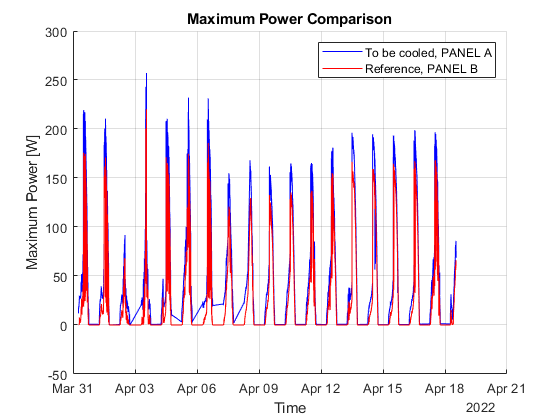

s31 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.max_power_mW./1000, 'b')
plot(B3max_data_tt.datetime, B3max_data_tt.max_power_mW./1000, 'r')
ylabel('Maximum Power [W]')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('Maximum Power Comparison')
saveas(s31, "Figures/" + folder_name3 + "/power_comparison.fig");
saveas(s31, "Figures/" + folder_name3 + "/power_comparison.png");

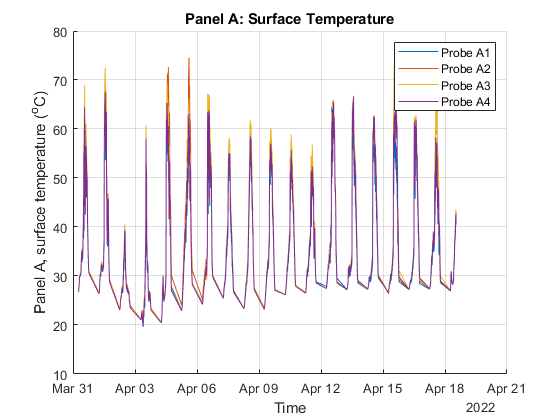


s32 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.A0_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A1_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A2_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A3_temp)
ylabel('Panel A, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4')
title('Panel A: Surface Temperature')
saveas(s32, "Figures/" + folder_name3 + "/Panel A surface temperature.fig");
saveas(s32, "Figures/" + folder_name3 + "/Panel A surface temperature.png");

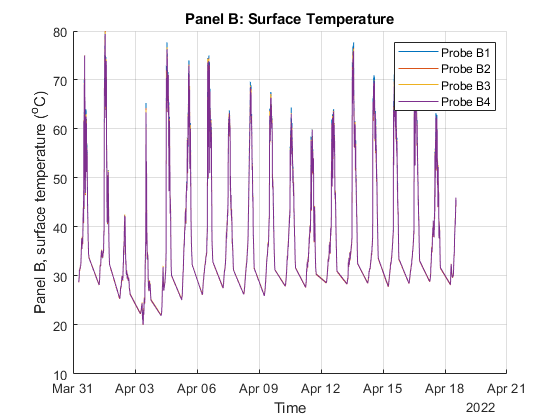

general_time_limit = get(gca, 'XLim');
general_surfaceTemp_limit = get(gca, 'YLim');

s33 = figure;
hold on
grid
plot(B3max_data_tt.datetime, B3max_data_tt.B0_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B1_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B2_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B3_temp)
ylabel('Panel B, surface temperature (^oC)')
xlabel('Time')
legend('Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('Panel B: Surface Temperature')
xlim(general_time_limit)
ylim(general_surfaceTemp_limit)
saveas(s33, "Figures/" + folder_name3 + "/Panel B surface temperature.fig");
saveas(s33, "Figures/" + folder_name3 + "/Panel B surface temperature.png");

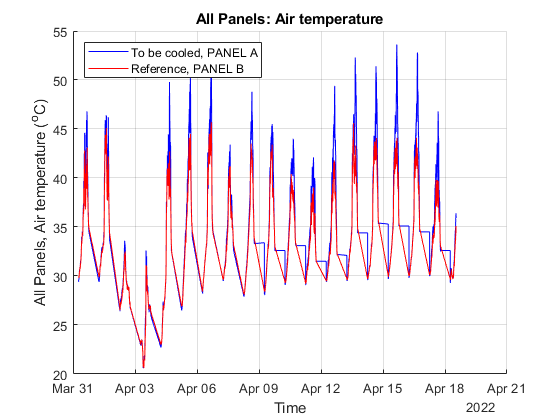


s34 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.amb_temp, 'b')
plot(B3max_data_tt.datetime, B3max_data_tt.amb_temp, 'r')
ylabel('All Panels, Air temperature (^oC)')
xlabel('Time')
legend({'To be cooled, PANEL A', 'Reference, PANEL B'},'Location','northwest')
title('All Panels: Air temperature')
saveas(s34, "Figures/" + folder_name3 + "/All air temperature.fig");
saveas(s34, "Figures/" + folder_name3 + "/All air temperature.png");

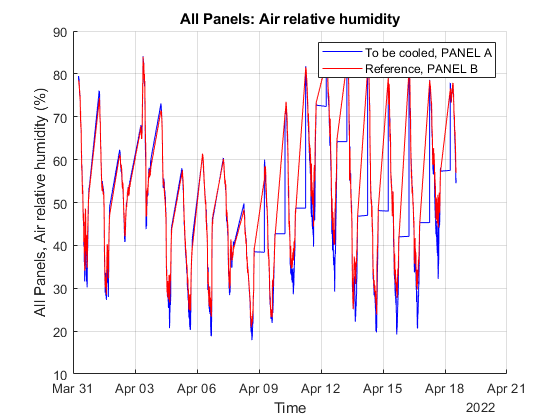


s35 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.amb_humid, 'b')
plot(B3max_data_tt.datetime, B3max_data_tt.amb_humid, 'r')
ylabel('All Panels, Air relative humidity (%)')
xlabel('Time')
legend('To be cooled, PANEL A', 'Reference, PANEL B')
title('All Panels: Air relative humidity')
saveas(s35, "Figures/" + folder_name3 + "/All air relative humidity.fig");
saveas(s35, "Figures/" + folder_name3 + "/All air relative humidity.png");

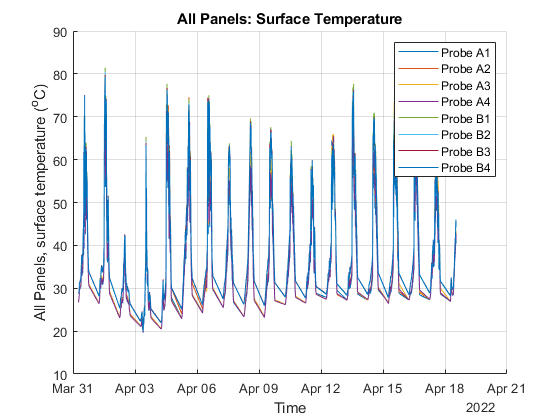



s36 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.A0_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A1_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A2_temp)
plot(A3max_data_tt.datetime, A3max_data_tt.A3_temp)

plot(B3max_data_tt.datetime, B3max_data_tt.B0_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B1_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B2_temp)
plot(B3max_data_tt.datetime, B3max_data_tt.B3_temp)
ylabel('All Panels, surface temperature (^oC)')
xlabel('Time')
legend('Probe A1', 'Probe A2', 'Probe A3', 'Probe A4', 'Probe B1', 'Probe B2', 'Probe B3', 'Probe B4')
title('All Panels: Surface Temperature')
saveas(s36, "Figures/" + folder_name3 + "/All surface temperature.fig");
saveas(s36, "Figures/" + folder_name3 + "/All surface temperature.png");

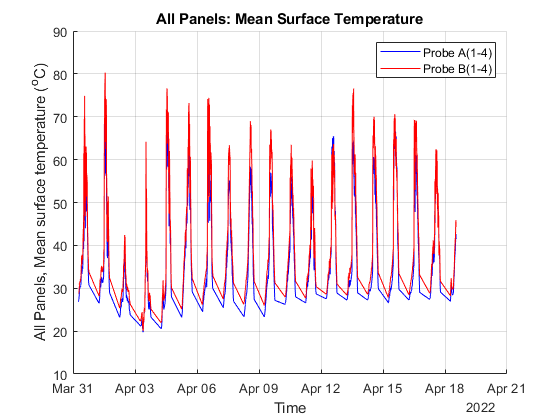



s37 = figure;
hold on
grid
plot(A3max_data_tt.datetime, A3max_data_tt.meanTemp, 'b')
plot(B3max_data_tt.datetime, B3max_data_tt.meanTemp, 'r')

ylabel('All Panels, Mean surface temperature (^oC)')
xlabel('Time')
legend('Probe A(1-4)', 'Probe B(1-4)')
title('All Panels: Mean Surface Temperature')
saveas(s37, "Figures/" + folder_name3 + "/All mean surface temperature.fig");
saveas(s37, "Figures/" + folder_name3 + "/All mean surface temperature.png");

## Aggregate (mean) 10 Mins

method3 = 'mean';
dt3 = minutes(10);
A3max_data_tt2 = retime(A3max_data_tt,'regular',method3,'TimeStep',dt3);
B3max_data_tt2 = retime(B3max_data_tt,'regular',method3,'TimeStep',dt3);

start_analyse_time3 = datetime(2022,3,5,0,0,0);
A3max_data_tt2 = A3max_data_tt2(A3max_data_tt2.datetime > start_analyse_time3,:);
B3max_data_tt2 = B3max_data_tt2(B3max_data_tt2.datetime > start_analyse_time3,:);

if A3max_data_tt2.datetime(end) > B3max_data_tt2.datetime(end)
    A3max_data_tt2 = A3max_data_tt2(A3max_data_tt2.datetime <= B3max_data_tt2.datetime(end),:);
elseif B3max_data_tt2.datetime(end) > A3max_data_tt2.datetime(end)
    B3max_data_tt2 = B3max_data_tt2(B3max_data_tt2.datetime <= A3max_data_tt2.datetime(end),:);
end

joined_tt3 = innerjoin(A3max_data_tt2, B3max_data_tt2, 'Keys', 'datetime');
joined_tt3_clean_tmp = joined_tt3(~any(ismissing(joined_tt3),2),:);
joined_tt3_clean_tmp = joined_tt3_clean_tmp(joined_tt3_clean_tmp.max_power_mW_B3max_data_tt2 >= 10000, :);

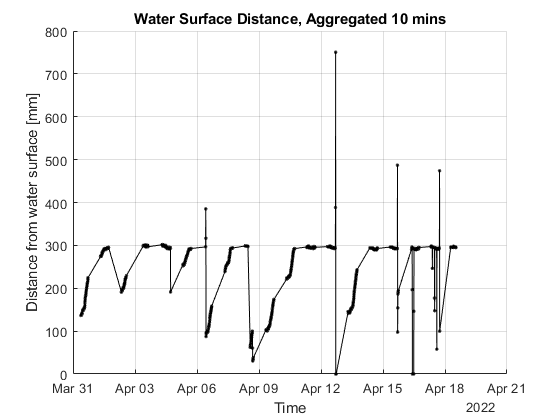

s312 = figure;
hold on
grid
plot(joined_tt3_clean_tmp.datetime, joined_tt3_clean_tmp.Distance_from_water_mm, '.-k')

ylabel('Distance from water surface [mm]')
xlabel('Time')
title('Water Surface Distance, Aggregated 10 mins')
saveas(s312, "Figures/" + folder_name3 + "/water_distance.fig");
saveas(s312, "Figures/" + folder_name3 + "/water_distance.png");

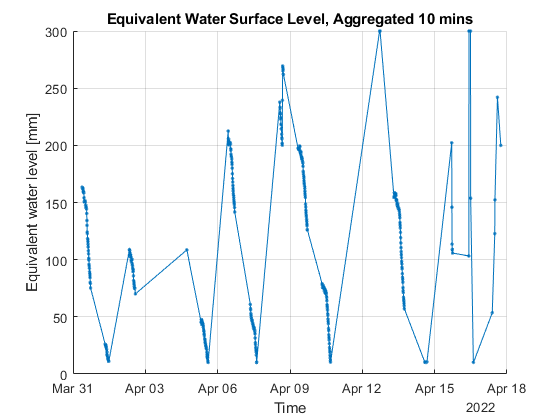

approx_base_distance = 300; % mm
joined_tt3_clean_tmp.water_level = approx_base_distance - joined_tt3_clean_tmp.Distance_from_water_mm;

cooled = true;
limit_waterlevel = 10.0;
joined_tt3_clean = joined_tt3_clean_tmp(joined_tt3_clean_tmp.water_level >= limit_waterlevel, :);
%joined_tt3_clean = joined_tt3_clean_tmp(joined_tt3_clean_tmp.water_level < 10.0, :);

s313 = figure;
hold on
grid
plot(joined_tt3_clean.datetime, joined_tt3_clean.water_level, '.-')

ylabel('Equivalent water level [mm]')
xlabel('Time')
title('Equivalent Water Surface Level, Aggregated 10 mins')

if cooled
    saveas(s313, "Figures/" + folder_name3 + "/water_level.fig");
    saveas(s313, "Figures/" + folder_name3 + "/water_level.png");
else
    saveas(s313, "Figures/" + folder_name3 + "/uncooled_water_level.fig");
    saveas(s313, "Figures/" + folder_name3 + "/uncooled_water_level.png");
end

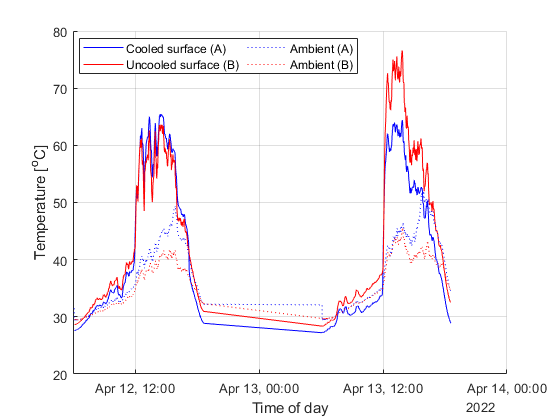

% 13 Apr: good for example
if cooled
    A_example = A3max_data_tt(A3max_data_tt.datetime >= datetime(2022,4,12,0,0,0), :);
    A_example = A_example(A_example.datetime < datetime(2022,4,14,0,0,0), :);
    B_example = B3max_data_tt(B3max_data_tt.datetime >= datetime(2022,4,12,0,0,0), :);
    B_example = B_example(B_example.datetime < datetime(2022,4,14,0,0,0), :);
    
    s_Ex1 = figure;
    hold on
    grid on
    % plot(A_example.datetime, A_example.max_power_mW./1000, '-b')
    % plot(B_example.datetime, B_example.max_power_mW./1000, '-r')
    plot(A_example.datetime, A_example.meanTemp, '-b')
    plot(B_example.datetime, B_example.meanTemp, '-r')
    plot(A_example.datetime, A_example.amb_temp, ':b')
    plot(B_example.datetime, B_example.amb_temp, ':r')
    %'Color', [0.1 0.8 0.1]
    %'Color', [0.9290 0.6940 0.1250]
    ylabel('Temperature [^oC]')
    xlabel('Time of day')
    %title('Equivalent Water Surface Level, Aggregated 10 mins')
    legend({'Cooled surface (A)', 'Uncooled surface (B)', 'Ambient (A)', 'Ambient (B)'}, ...
        'Location', 'best', ...
        'NumColumns', 2)
    saveas(s_Ex1, "Figures/" + folder_name3 + "/temp_example.fig");
    saveas(s_Ex1, "Figures/" + folder_name3 + "/temp_example.png");
end

## Prediction

max_mW_A3 = joined_tt3_clean.max_power_mW_A3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 > 2000.0);
max_mW_B3 = joined_tt3_clean.max_power_mW_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 > 2000.0);

mdl3 = fitlm(max_mW_B3, max_mW_A3)

mdl3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue  
                   ________    _________    ______    _________

    (Intercept)      15409        647.35    23.804    1.498e-81
    x1              1.1354     0.0084518    134.34            0


Number of observations: 450, Error degrees of freedom: 448
Root Mean Squared Error: 8.12e+03
R-squared: 0.976,  Adjusted R-Squared: 0.976
F-statistic vs. constant model: 1.8e+04, p-value = 0

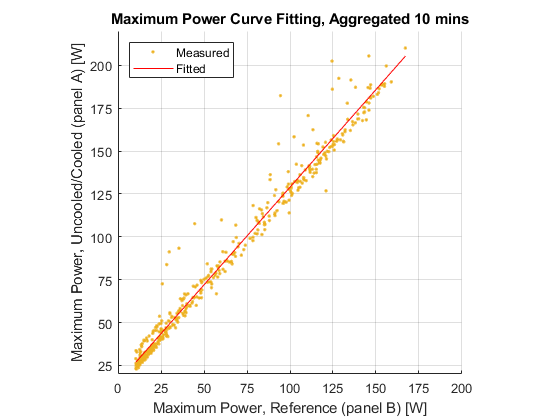

%lm2 = fitlm(joined_tt_clean,'max_power_mW_Amax_data_tt2~max_power_mW_Bmax_data_tt2')

A3pred = predict(mdl3,joined_tt3_clean.max_power_mW_B3max_data_tt2);
A3pred_with_refModel = predict(mdl,joined_tt3_clean.max_power_mW_B3max_data_tt2);
A3_diff = A3pred - A3pred_with_refModel;

s38 = figure;
hold on
grid
%plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, joined_tt_clean.max_power_mW_Amax_data_tt2./1000, '.')
plot(max_mW_B3./1000, max_mW_A3./1000, '.', 'Color', [0.9290 0.6940 0.1250])
plot(joined_tt3_clean.max_power_mW_B3max_data_tt2./1000, A3pred./1000, '-r')
ylabel('Maximum Power, Uncooled/Cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Measured', 'Fitted'},'Location','northwest')
title('Maximum Power Curve Fitting, Aggregated 10 mins')
set(gca,'xtick',[0:25:200])
set(gca,'ytick',[0:25:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square
if cooled
    saveas(s38, "Figures/" + folder_name3 + "/power_comparison_10calCurve.fig");
    saveas(s38, "Figures/" + folder_name3 + "/power_comparison_10calCurve.png");
else
    saveas(s38, "Figures/" + folder_name3 + "/uncooled_power_comparison_10calCurve.fig");
    saveas(s38, "Figures/" + folder_name3 + "/uncooled_power_comparison_10calCurve.png");
end

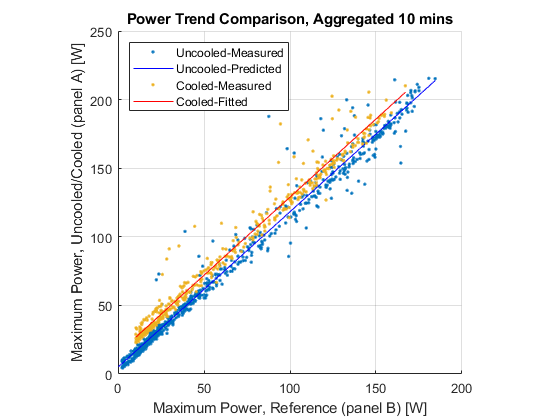

s39 = figure;
hold on
grid
plot(max_mW_B./1000, max_mW_A./1000, '.')
plot(joined_tt_clean.max_power_mW_Bmax_data_tt2./1000, Apred./1000, '-b')
plot(max_mW_B3./1000, max_mW_A3./1000, '.')
plot(joined_tt3_clean.max_power_mW_B3max_data_tt2./1000, A3pred./1000, '-r')
ylabel('Maximum Power, Uncooled/Cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Uncooled-Measured', 'Uncooled-Predicted', 'Cooled-Measured', 'Cooled-Fitted'},'Location','northwest')
title('Power Trend Comparison, Aggregated 10 mins')
% set(gca,'xtick',[0:10:200])
% set(gca,'ytick',[0:25:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square

if cooled
    saveas(s39, "Figures/" + folder_name3 + "/calCurve_compare.fig");
    saveas(s39, "Figures/" + folder_name3 + "/calCurve_compare.png");
else
    saveas(s39, "Figures/" + folder_name3 + "/uncooled_calCurve_compare.fig");
    saveas(s39, "Figures/" + folder_name3 + "/uncooled_calCurve_compare.png");
end

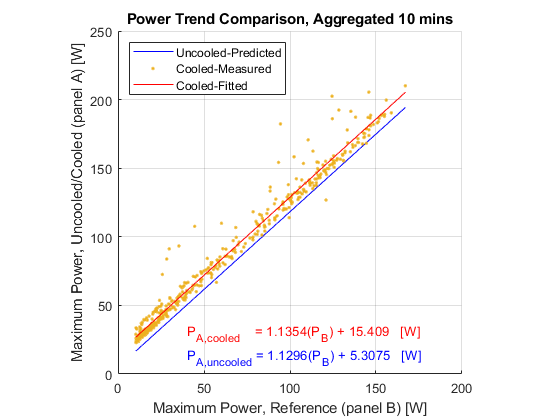

s310 = figure;
hold on
grid
%plot(max_mW_B./1000, max_mW_A./1000, '.')
plot(joined_tt3_clean.max_power_mW_B3max_data_tt2./1000, A3pred_with_refModel./1000, '-b')
plot(max_mW_B3./1000, max_mW_A3./1000, '.', 'Color', [0.9290 0.6940 0.1250])
plot(joined_tt3_clean.max_power_mW_B3max_data_tt2./1000, A3pred./1000, '-r')
ylabel('Maximum Power, Uncooled/Cooled (panel A) [W]')
xlabel('Maximum Power, Reference (panel B) [W]')
legend({'Uncooled-Predicted', 'Cooled-Measured', 'Cooled-Fitted'},'Location','northwest')
title('Power Trend Comparison, Aggregated 10 mins')
axis square
% set(gca,'xtick',[0:20:200])
% set(gca,'ytick',[0:20:250])
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
xl = xlim;
yl = ylim;
xt = 0.20 * (xl(2)-xl(1)) + xl(1);
yt = 0.05 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('P_A_,_u_n_c_o_o_l_e_d = %1.4f(P_B) + %1.4f   [W]', mdl.Coefficients.Estimate(2), abs(mdl.Coefficients.Estimate(1))/1000);
text(xt, yt, caption, 'FontSize', 10, 'Color', 'b');

xl = xlim;
yl = ylim;
xt = 0.20 * (xl(2)-xl(1)) + xl(1);
yt = 0.12 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('P_A_,_c_o_o_l_e_d    = %1.4f(P_B) + %2.3f   [W]', mdl3.Coefficients.Estimate(2), abs(mdl3.Coefficients.Estimate(1))/1000);
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');

if cooled
    saveas(s310, "Figures/" + folder_name3 + "/predictCalCurve.fig");
    saveas(s310, "Figures/" + folder_name3 + "/predictCalCurve.png");
else
    saveas(s310, "Figures/" + folder_name3 + "/uncooled_predictCalCurve.fig");
    saveas(s310, "Figures/" + folder_name3 + "/uncooled_predictCalCurve.png");
end

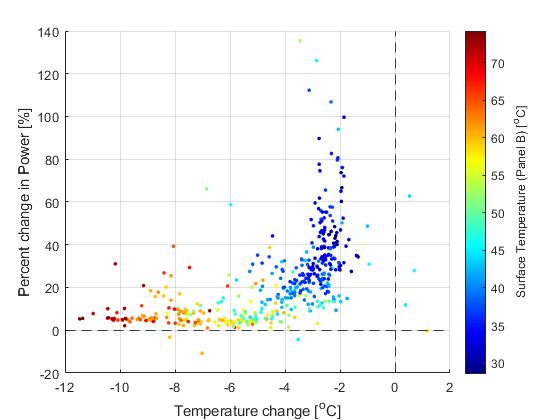

% power difference
s310n = figure;
hold on
grid

power_diff_mW = (joined_tt3_clean.max_power_mW_A3max_data_tt2 - A3pred_with_refModel);
power_percent = (joined_tt3_clean.max_power_mW_A3max_data_tt2 - A3pred_with_refModel)./(A3pred_with_refModel)*100;

% A3pred_with_refModel
% plot(joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     (joined_tt3_clean.max_power_mW_A3max_data_tt2 - A3pred_with_refModel)./(A3pred_with_refModel), '.r')
scatter(joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    power_percent, ...
    8, joined_tt3_clean.meanTemp_B3max_data_tt2,'filled')
colorbar
colormap jet
h4n = colorbar;
ylabel(h4n, 'Surface Temperature (Panel B) [^oC]')
ylabel('Percent change in Power [%]')
xlabel('Temperature change [^oC]')
%title('Percent change in Power, Aggregated 10 mins')
yline(0, '--k');
xline(0, '--k');

if cooled
    saveas(s310n, "Figures/" + folder_name3 + "/percentPower_byTempDrop.fig");
    saveas(s310n, "Figures/" + folder_name3 + "/percentPower_byTempDrop.png");
else
    saveas(s310n, "Figures/" + folder_name3 + "/uncooled_percentPower_byTempDrop.fig");
    saveas(s310n, "Figures/" + folder_name3 + "/uncooled_percentPower_byTempDrop.png");
end

% power difference - relative temperature

avg_ambientTemp = (joined_tt3_clean.amb_temp_A3max_data_tt2 + joined_tt3_clean.amb_temp_B3max_data_tt2)./2;
avg_ambientRH = (joined_tt3_clean.amb_humid_A3max_data_tt2 + joined_tt3_clean.amb_humid_B3max_data_tt2)./2;
relative_temp = ((joined_tt3_clean.meanTemp_A3max_data_tt2 - avg_ambientTemp)./(joined_tt3_clean.meanTemp_B3max_data_tt2 - avg_ambientTemp));
%{
s310t = figure;
hold on
grid
scatter((relative_temp*100), ...
    power_percent, ...
    8, joined_tt3_clean.meanTemp_B3max_data_tt2,'filled')
colorbar
colormap jet
h4t = colorbar;


ylabel(h4t, 'Panel B Surface Temperature Power [^oC]')
ylabel('Percent change in Power [%]')
xlabel('Relative temperature change [%]')
title('Percent change in Power, Aggregated 10 mins')
yline(0, '--k');
xline(0, '--k');
xlim([-1500 1500])

if cooled
    saveas(s310t, "Figures/" + folder_name3 + "/percentPower_byrelTempDrop.fig");
    saveas(s310t, "Figures/" + folder_name3 + "/percentPower_byrelTempDrop.png");
else
    saveas(s310t, "Figures/" + folder_name3 + "/uncooled_percentPower_byrelTempDrop.fig");
    saveas(s310t, "Figures/" + folder_name3 + "/uncooled_percentPower_byrelTempDrop.png");
end
%}

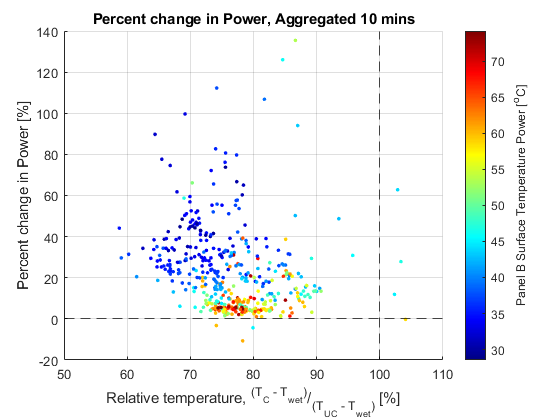

% power difference - relative temperature dry/wet-bulb
wet_temp = avg_ambientTemp .* atan(0.151977 .* (avg_ambientRH + 8.313659).^(1/2)) + atan(avg_ambientTemp + avg_ambientRH) - atan(avg_ambientRH - 1.676331) + 0.00391838 .*(avg_ambientRH).^(3/2) .* atan(0.023101 .* avg_ambientRH) - 4.686035;
relative_temp_wet = ((joined_tt3_clean.meanTemp_A3max_data_tt2 - wet_temp)./(joined_tt3_clean.meanTemp_B3max_data_tt2 - wet_temp));

s310t2 = figure;
hold on
grid

scatter((relative_temp_wet*100), ...
    power_percent, ...
    8, joined_tt3_clean.meanTemp_B3max_data_tt2,'filled')
colorbar
colormap jet
h4t = colorbar;


ylabel(h4t, 'Panel B Surface Temperature Power [^oC]')
ylabel('Percent change in Power [%]')
xlabel('Relative temperature, ^{(T_C - T_{wet})}/_{(T_{UC} - T_{wet})} [%]')
%xlabel('$\frac{T_C - T_{wet}}{T_{UC} - T_{wet}}$', 'Interpreter','latex')
title('Percent change in Power, Aggregated 10 mins')
yline(0, '--k');
xline(100, '--k');

if cooled
    saveas(s310t2, "Figures/" + folder_name3 + "/percentPower_byrelTempDrop_wet.fig");
    saveas(s310t2, "Figures/" + folder_name3 + "/percentPower_byrelTempDrop_wet.png");
else
    saveas(s310t2, "Figures/" + folder_name3 + "/uncooled_percentPower_byrelTempDrop_wet.fig");
    saveas(s310t2, "Figures/" + folder_name3 + "/uncooled_percentPower_byrelTempDrop_wet.png");
end

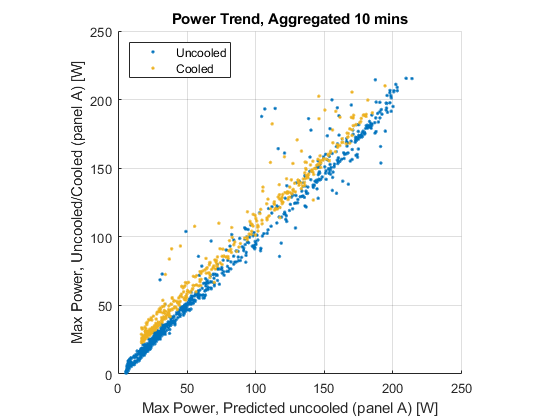

% On validation plot
s310v = figure;
hold on
grid

plot(Apred./1000, joined_tt_clean.max_power_mW_Amax_data_tt2./1000, '.')
plot(A3pred_with_refModel./1000, joined_tt3_clean.max_power_mW_A3max_data_tt2./1000, '.', 'Color', [0.9290 0.6940 0.1250])
ylabel('Max Power, Uncooled/Cooled (panel A) [W]')
xlabel('Max Power, Predicted uncooled (panel A) [W]')
title('Power Trend, Aggregated 10 mins')
legend({'Uncooled', 'Cooled'},'Location','northwest')
axis square

if cooled
    saveas(s310v, "Figures/" + folder_name3 + "/compare_on_validation_plot.fig");
    saveas(s310v, "Figures/" + folder_name3 + "/compare_on_validation_plot.png");
else
    saveas(s310v, "Figures/" + folder_name3 + "/uncooled_compare_on_validation_plot.fig");
    saveas(s310v, "Figures/" + folder_name3 + "/uncooled_compare_on_validation_plot.png");
end

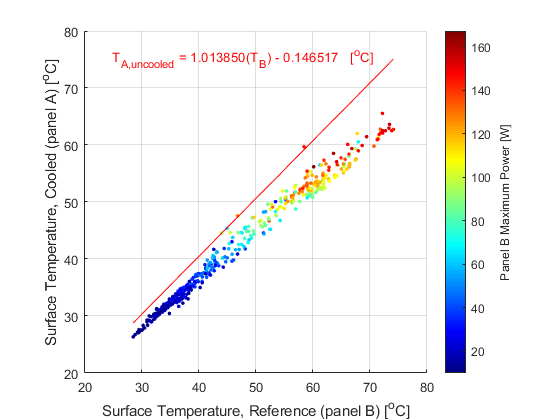

s311 = figure;
hold on
grid

meanTemp_A3_full = joined_tt3_clean.meanTemp_A3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 0.0);
meanTemp_B3_full = joined_tt3_clean.meanTemp_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 0.0);

A3pred_temp = predict(mdl_temp, meanTemp_B3_full);

scatter(meanTemp_B3_full, meanTemp_A3_full, 8, joined_tt3_clean.max_power_mW_B3max_data_tt2./1000,'filled')
colorbar
colormap jet
h4 = colorbar;
plot(meanTemp_B3_full, A3pred_temp, '-r')
xl = xlim;
yl = ylim;
xt = 0.08 * (xl(2)-xl(1)) + xl(1);
yt = 0.92 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('T_{A,uncooled} = %f(T_B) - %f   [^oC]', mdl_temp.Coefficients.Estimate(2), abs(mdl_temp.Coefficients.Estimate(1)));
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');
ylabel(h4, 'Panel B Maximum Power [W]')
ylabel('Surface Temperature, Cooled (panel A) [^oC]')
xlabel('Surface Temperature, Reference (panel B) [^oC]')
%legend({'Measured', 'Predicted'},'Location','northwest')
%title('Surface Temperature, Aggregated 10 mins')
%power_limit = get(gca, 'YLim');
%xlim(power_limit)
axis square

if cooled
    saveas(s311, "Figures/" + folder_name3 + "/temperature_trend.fig");
    saveas(s311, "Figures/" + folder_name3 + "/temperature_trend.png");
else
    saveas(s311, "Figures/" + folder_name3 + "/uncooled_temperature_trend.fig");
    saveas(s311, "Figures/" + folder_name3 + "/uncooled_temperature_trend.png");
end

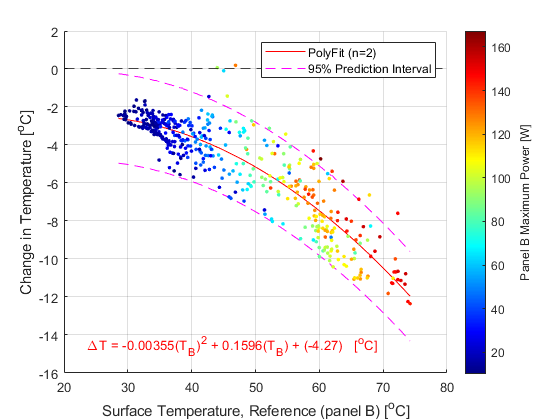

% Decrease in temperature
s311a = figure;
hold on
grid

temp_change = meanTemp_A3_full - A3pred_temp;
[p,S] = polyfit(meanTemp_B3_full, temp_change, 2);
[temp_change_fit, delta] = polyval(p, meanTemp_B3_full, S);

change_table = table(meanTemp_B3_full, temp_change_fit);
change_table = sortrows(change_table,'meanTemp_B3_full','ascend');

plot(change_table.meanTemp_B3_full, change_table.temp_change_fit, 'r-')
plot(change_table.meanTemp_B3_full, change_table.temp_change_fit+2*delta, 'm--', ...
    change_table.meanTemp_B3_full, change_table.temp_change_fit-2*delta, 'm--')

scatter(meanTemp_B3_full, temp_change, 8, joined_tt3_clean.max_power_mW_B3max_data_tt2./1000,'filled')
colorbar
colormap jet
h5 = colorbar;

yline(0, '--k');

xl = xlim;
yl = ylim;
xt = 0.06 * (xl(2)-xl(1)) + xl(1);
yt = 0.08 * (yl(2)-yl(1)) + yl(1);
caption = strcat('\Delta', sprintf('T = %1.5f(T_B)^2 + %1.4f(T_B) + (%1.2f)   [^oC]', p(1), p(2), p(3)));
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');

legend({'PolyFit (n=2)','95% Prediction Interval'}, 'Location', 'northeast')
ylabel(h5, 'Panel B Maximum Power [W]')
ylabel('Change in Temperature [^oC]')
xlabel('Surface Temperature, Reference (panel B) [^oC]')
%title('Change in Temperature, Aggregated 10 mins')

if cooled
    saveas(s311a, "Figures/" + folder_name3 + "/change_in_temperature.fig");
    saveas(s311a, "Figures/" + folder_name3 + "/change_in_temperature.png");
else
    saveas(s311a, "Figures/" + folder_name3 + "/uncooled_change_in_temperature.fig");
    saveas(s311a, "Figures/" + folder_name3 + "/uncooled_change_in_temperature.png");
end

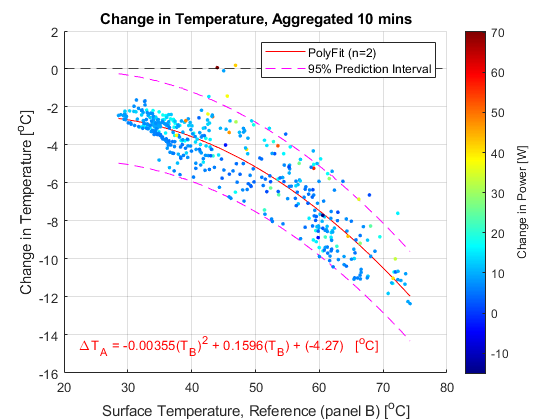

% Decrease in temperature
s311b = figure;
hold on
grid

plot(change_table.meanTemp_B3_full, change_table.temp_change_fit, 'r-')
plot(change_table.meanTemp_B3_full, change_table.temp_change_fit+2*delta, 'm--', ...
    change_table.meanTemp_B3_full, change_table.temp_change_fit-2*delta, 'm--')

scatter(meanTemp_B3_full, temp_change, 8, power_diff_mW./1000,'filled')
colorbar
colormap jet
h5 = colorbar;

yline(0, '--k');

xl = xlim;
yl = ylim;
xt = 0.04 * (xl(2)-xl(1)) + xl(1);
yt = 0.08 * (yl(2)-yl(1)) + yl(1);
caption = strcat('\Delta', sprintf('T_A = %1.5f(T_B)^2 + %1.4f(T_B) + (%1.2f)   [^oC]', p(1), p(2), p(3)));
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');

legend({'PolyFit (n=2)','95% Prediction Interval'}, 'Location', 'northeast')
%ylabel(h5, 'Panel B Maximum Power [W]')
ylabel(h5, 'Change in Power [W]')
ylabel('Change in Temperature [^oC]')
xlabel('Surface Temperature, Reference (panel B) [^oC]')
title('Change in Temperature, Aggregated 10 mins')

if cooled
    saveas(s311b, "Figures/" + folder_name3 + "/change_in_temperature_percentPower.fig");
    saveas(s311b, "Figures/" + folder_name3 + "/change_in_temperature_percentPower.png");
else
    saveas(s311b, "Figures/" + folder_name3 + "/uncooled_change_in_temperature_percentPower.fig");
    saveas(s311b, "Figures/" + folder_name3 + "/uncooled_change_in_temperature_percentPower.png");
end

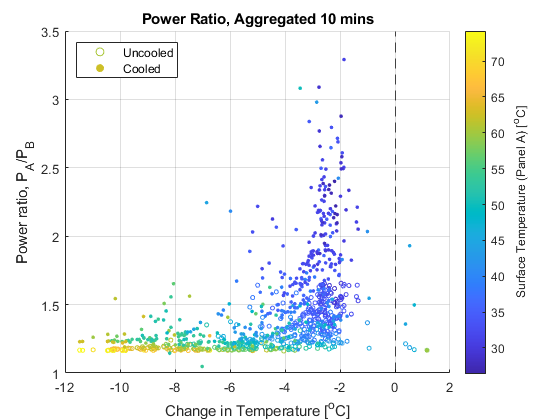

% Efficiency - convert from lux: 0.0079 W/m2 per Lux
area = 156*156*72/(1e6);
joined_tt3_clean.power_in = 0.0079*area*joined_tt3_clean.Lux;
joined_tt3_clean.eff_A = (joined_tt3_clean.max_power_mW_A3max_data_tt2 ./ (joined_tt3_clean.power_in*1000)) .*100;
joined_tt3_clean.eff_B = (joined_tt3_clean.max_power_mW_B3max_data_tt2 ./ (joined_tt3_clean.power_in*1000)) .*100;
joined_tt3_clean.eff_A_calibrated = (predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2) ./ (joined_tt3_clean.power_in*1000)) .*100;
joined_tt3_clean.eff_increase = joined_tt3_clean.eff_A - joined_tt3_clean.eff_A_calibrated;
joined_tt3_clean.PA_PB = joined_tt3_clean.max_power_mW_A3max_data_tt2 ./ joined_tt3_clean.max_power_mW_B3max_data_tt2;
joined_tt3_clean.PAcal_PB = predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2) ./ joined_tt3_clean.max_power_mW_B3max_data_tt2;

s311e = figure;
hold on
grid

% plot(joined_tt3_clean.meanTemp_A3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000) - ...
%     joined_tt3_clean.meanTemp_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), ...
%     joined_tt3_clean.PAcal_PB(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), '.')
% plot(joined_tt3_clean.meanTemp_A3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000) - ...
%     joined_tt3_clean.meanTemp_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), ...
%     joined_tt3_clean.PA_PB(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), '.r')

scatter(joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    joined_tt3_clean.PAcal_PB, ...
    10, ...
    joined_tt3_clean.meanTemp_B3max_data_tt2)

scatter(joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    joined_tt3_clean.PA_PB, ...
    8, ...
    joined_tt3_clean.meanTemp_A3max_data_tt2, 'filled')

% scatter(joined_tt3_clean.meanTemp_A3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000) - ...
%     joined_tt3_clean.meanTemp_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), ...
%     joined_tt3_clean.eff_increase(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000), ...
%     8, joined_tt3_clean.meanTemp_B3max_data_tt2(joined_tt3_clean.max_power_mW_B3max_data_tt2 >= 10000),'filled')
%ylim([-10 10])
colorbar
% colormap jet
h6 = colorbar;
ylabel(h6, 'Surface Temperature (Panel A) [^oC]')

xline(0, '--k')
legend({'Uncooled','Cooled'}, 'Location', 'northwest')
ylabel('Power ratio, P_A/P_B')
xlabel('Change in Temperature [^oC]')
title('Power Ratio, Aggregated 10 mins')

if cooled
    saveas(s311e, "Figures/" + folder_name3 + "/change_in_efficiency.fig");
    saveas(s311e, "Figures/" + folder_name3 + "/change_in_efficiency.png");
else
    saveas(s311e, "Figures/" + folder_name3 + "/uncooled_change_in_efficiency.fig");
    saveas(s311e, "Figures/" + folder_name3 + "/uncooled_change_in_efficiency.png");
end

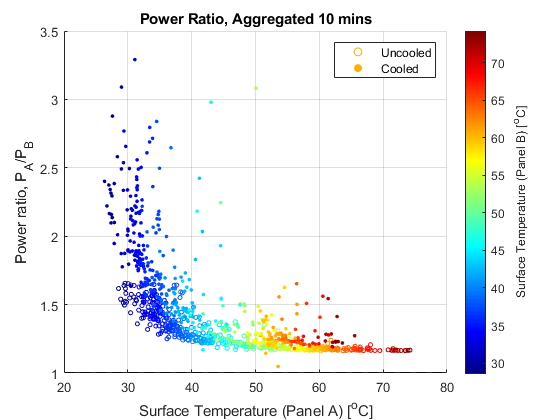

% Change in Power - by surface temp of Cooled A - Color: change in temp
s310nn = figure;
hold on
grid

% plot(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.PAcal_PB, '.')
% plot(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.PA_PB, '.')

%% panel B temp ~ panel A uncooled
scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    joined_tt3_clean.PAcal_PB, ...
    10, ...
    joined_tt3_clean.meanTemp_B3max_data_tt2)

% panel A cooled
scatter(joined_tt3_clean.meanTemp_A3max_data_tt2, ...
    joined_tt3_clean.PA_PB, ...
    8, ...
    joined_tt3_clean.meanTemp_B3max_data_tt2, 'filled')
% joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt

colorbar
colormap jet
h4nn = colorbar;
ylabel(h4nn, 'Surface Temperature (Panel B) [^oC]')
ylabel('Power ratio, P_A/P_B')
xlabel('Surface Temperature (Panel A) [^oC]')
title('Power Ratio, Aggregated 10 mins')
yline(1, '--k');
%xline(45, '--k');
legend({'Uncooled', 'Cooled'}, 'Location', 'northeast')

if cooled
    saveas(s310nn, "Figures/" + folder_name3 + "/percentPower_byTempA.fig");
    saveas(s310nn, "Figures/" + folder_name3 + "/percentPower_byTempA.png");
else
    saveas(s310nn, "Figures/" + folder_name3 + "/uncooled_percentPower_byTempA.fig");
    saveas(s310nn, "Figures/" + folder_name3 + "/uncooled_percentPower_byTempA.png");
end

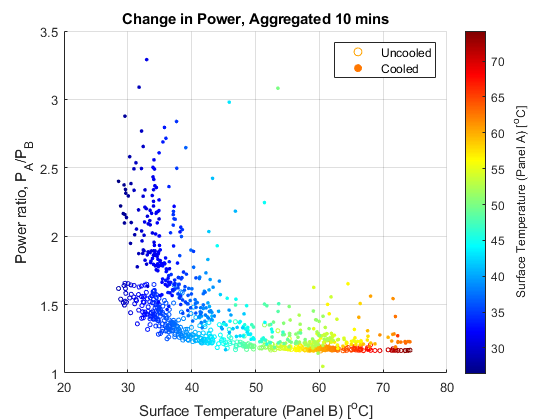

s310nnn = figure;
hold on
grid

%% panel B temp ~ panel A uncooled
% scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.max_power_mW_A3max_data_tt2 - predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2), ...
%     10, ...
%     joined_tt3_clean.meanTemp_B3max_data_tt2)

% panel A cooled
% scatter(joined_tt3_clean.meanTemp_A3max_data_tt2, ...
%     (joined_tt3_clean.max_power_mW_A3max_data_tt2 - predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2))./1000, ...
%     8, ...
%     joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, 'filled')
% joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt

scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    joined_tt3_clean.PAcal_PB, ...
    10, ...
    joined_tt3_clean.meanTemp_B3max_data_tt2)

scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    joined_tt3_clean.PA_PB, ...
    8, ...
    joined_tt3_clean.meanTemp_A3max_data_tt2, 'filled')

colorbar
colormap jet
h4nnn = colorbar;
ylabel(h4nnn, 'Surface Temperature (Panel A) [^oC]')
ylabel('Power ratio, P_A/P_B')
xlabel('Surface Temperature (Panel B) [^oC]')
title('Change in Power, Aggregated 10 mins')
%yline(1, '--k');
%xline(45, '--k');
legend({'Uncooled', 'Cooled'}, 'Location', 'northeast')

if cooled
    saveas(s310nnn, "Figures/" + folder_name3 + "/changePower_byTempA.fig");
    saveas(s310nnn, "Figures/" + folder_name3 + "/changePower_byTempA.png");
else
    saveas(s310nnn, "Figures/" + folder_name3 + "/uncooled_changePower_byTempA.fig");
    saveas(s310nnn, "Figures/" + folder_name3 + "/uncooled_changePower_byTempA.png");
end

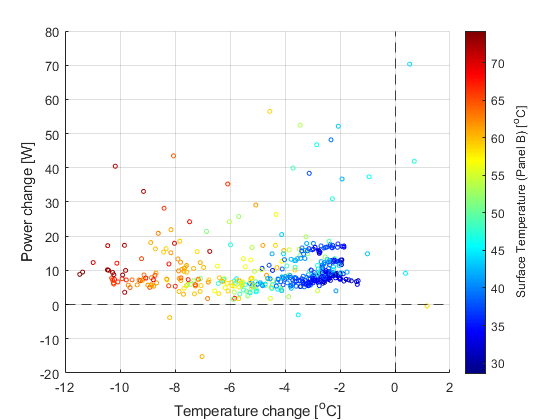

s310nnnn = figure;
hold on
grid

%% panel B temp ~ panel A uncooled
scatter(joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, ...
    (joined_tt3_clean.max_power_mW_A3max_data_tt2 - predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2))./1000, ...
    10, ...
    joined_tt3_clean.meanTemp_B3max_data_tt2)

% panel A cooled
% scatter(joined_tt3_clean.meanTemp_A3max_data_tt2, ...
%     (joined_tt3_clean.max_power_mW_A3max_data_tt2 - predict(mdl, joined_tt3_clean.max_power_mW_B3max_data_tt2))./1000, ...
%     8, ...
%     joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt2, 'filled')
% joined_tt3_clean.meanTemp_A3max_data_tt2 - joined_tt3_clean.meanTemp_B3max_data_tt

% scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.PAcal_PB, ...
%     10, ...
%     joined_tt3_clean.meanTemp_B3max_data_tt2)

% scatter(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.meanTemp_A3max_data_tt2, ...
%     8, ...
%     (joined_tt3_clean.PA_PB - joined_tt3_clean.PAcal_PB)./joined_tt3_clean.PA_PB * 100, 'filled')

colorbar
colormap jet
h4nnnn = colorbar;
ylabel(h4nnnn, 'Surface Temperature (Panel B) [^oC]')

% plot3(joined_tt3_clean.meanTemp_B3max_data_tt2, ...
%     joined_tt3_clean.meanTemp_A3max_data_tt2, ...
%     (joined_tt3_clean.PA_PB - joined_tt3_clean.PAcal_PB)./joined_tt3_clean.PA_PB * 100, '.')

xlabel('Temperature change [^oC]')
ylabel('Power change [W]')
% zlabel('Percent change in Power ratio, P_A/P_B [%]')
%title('Change in Power, Aggregated 10 mins')
yline(0, '--k');
xline(0, '--k');
%legend({'Uncooled', 'Cooled'}, 'Location', 'northeast')

if cooled
    saveas(s310nnnn, "Figures/" + folder_name3 + "/percentPowerRatio_byTemp.fig");
    saveas(s310nnnn, "Figures/" + folder_name3 + "/percentPowerRatio_byTemp.png");
else
    saveas(s310nnnn, "Figures/" + folder_name3 + "/uncooled_percentPowerRatio_byTemp.fig");
    saveas(s310nnnn, "Figures/" + folder_name3 + "/uncooled_percentPowerRatio_byTemp.png");
end

# Trigger file reading

A4max_data = readtable("PanelA_" + subfix_name3 + "/TRIG_AF.TXT");
A4max_data.Properties.VariableNames = {'year', 'month', 'day', 'hour', 'minute', 'second', ...
    'V_oc','amb_temp', 'amb_humid', 'A0_temp', 'A1_temp', 'A2_temp', 'A3_temp', 'Distance_from_water_mm'};

A4max_data.datetime = datetime(...
    [A4max_data.year ...
    A4max_data.month ...
    A4max_data.day ...
    A4max_data.hour ...
    A4max_data.minute ...
    A4max_data.second]);
A4max_data = movevars(A4max_data,"datetime",'Before',"year");
A4_start_analyse_time = datetime(2022,3,25,0,0,0); % First day on Feb 6 / Data start Mar 25
A4max_data_tt = table2timetable(A4max_data(A4max_data.datetime > A4_start_analyse_time,:))

A4max_data_tt = 115939×14 timetable
          datetime          year    month    day    hour    minute    second    V_oc    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm
    ____________________    ____    _____    ___    ____    ______    ______    ____    ________    _________    _______    _______    _______    _______    ______________________

    25-Mar-2022 00:00:06    2022      3      25      0        0          6  

A4max_data_tt.meanTemp = mean([A4max_data_tt.A0_temp A4max_data_tt.A1_temp A4max_data_tt.A2_temp A4max_data_tt.A3_temp], 2)

A4max_data_tt = 115939×15 timetable
          datetime          year    month    day    hour    minute    second    V_oc    amb_temp    amb_humid    A0_temp    A1_temp    A2_temp    A3_temp    Distance_from_water_mm    meanTemp
    ____________________    ____    _____    ___    ____    ______    ______    ____    ________    _________    _______    _______    _______    _______    ______________________    ________

    25-Mar-2022 00:00:06

method4 = 'mean';
method5 = 'linear';
min_long = 15;
min_long2 = 30;
dt4 = minutes(min_long);
dt5 = minutes(min_long2);
% A4max_data_tt2 = unique(A4max_data_tt,'sort','rows');
% dupTimes = sort(A4max_data_tt.datetime);
% tf = (diff(dupTimes) == 0);
% dupTimes = dupTimes(tf);
% dupTimes = unique(dupTimes)
% A4max_data_tt(dupTimes,:)
% uniqueTimes = unique(A4max_data_tt.datetime)
A4max_data_tt2 = retime(A4max_data_tt,'regular',method4,'TimeStep',dt4);
A4max_data_tt3 = retime(A4max_data_tt2,'regular',method5,'TimeStep',dt5);

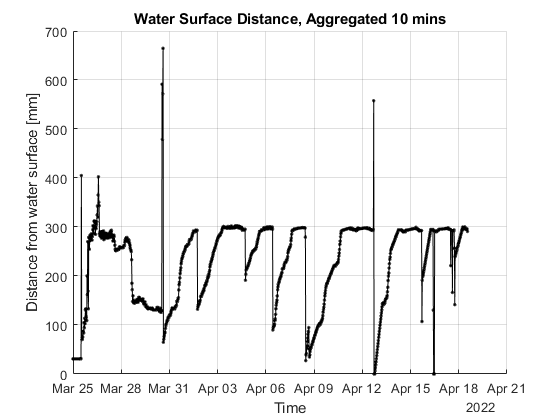

s41 = figure;
hold on
grid
plot(A4max_data_tt3.datetime, A4max_data_tt3.Distance_from_water_mm, '.-k')

ylabel('Distance from water surface [mm]')
xlabel('Time')
title('Water Surface Distance, Aggregated 10 mins')
saveas(s41, "Figures/" + folder_name3 + "/water_distance_full.fig");
saveas(s41, "Figures/" + folder_name3 + "/water_distance_full.png");

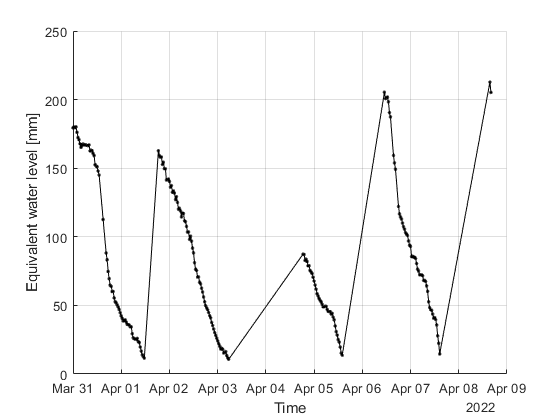

approx_base_distance = 300; % mm
water_table = table();
water_table.datetime = A4max_data_tt3.datetime;
water_table.level = approx_base_distance - A4max_data_tt3.Distance_from_water_mm;
water_table.A_temp = A4max_data_tt3.meanTemp;
water_table.air_temp = A4max_data_tt3.amb_temp;
%approx_water_level = approx_base_distance - A4max_data_tt.Distance_from_water_mm(A4max_data_tt.datetime >= datetime(2022,3,31,0,0,0));
water_table = water_table(water_table.datetime >= datetime(2022,3,31,0,0,0), :);
water_table = water_table(water_table.datetime < datetime(2022,4,9,0,0,0), :);
water_table = water_table(water_table.level >= 0.0, :);
water_table = water_table(water_table.level <= 220, :);
for i = 2:height(water_table)-1
    water_table.diff(i) = water_table.level(i+1) - water_table.level(i-1);
end
water_table.diff(1) = water_table.level(2) - water_table.level(1);
water_table.diff(height(water_table)) = water_table.level(height(water_table)) - water_table.level(height(water_table)-1);

select_water = water_table(abs(water_table.diff) <= 15, :);

s42 = figure;
hold on
grid
plot(select_water.datetime(select_water.level >= 10), ...
    select_water.level(select_water.level >= 10), '.-k')

ylabel('Equivalent water level [mm]')
xlabel('Time')
% title('Equivalent Water Surface Level')
saveas(s42, "Figures/" + folder_name3 + "/water_level_full.fig");
saveas(s42, "Figures/" + folder_name3 + "/water_level_full.png");

[p,S] = polyfit(select_water.A_temp(select_water.level >= 10), (select_water.diff(select_water.level >= 10)./min_long2).*60, 1);
[water_fit, water_delta] = polyval(p, select_water.A_temp(select_water.level >= 10), S);
fit_table = table(select_water.A_temp(select_water.level >= 10), water_fit);
fit_table = renamevars(fit_table,"Var1", ...
                 "A_temp")

fit_table = 232×2 table
    A_temp    water_fit
    ______    _________

     27.56     -8.0393 
    27.459     -8.0001 
    27.282     -7.9315 
     27.06     -7.8452 
     26.86     -7.7675 
    26.852     -7.7644 
    26.826     -7.7543 
    26.797     -7.7432 
    26.748      -7.724 
    26.741     -7.7214 
    26.631     -7.6787 
     26.71     -7.7093 
    26.851     -7.7639 
    27.192     -7.8965 
    28.171     -8.2764 
    29.743     -8.8869 


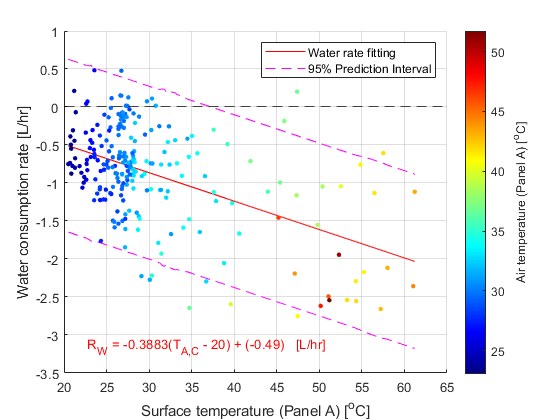

fit_table = sortrows(fit_table,'A_temp','ascend');

s42a = figure;
hold on
grid
plot(fit_table.A_temp, (fit_table.water_fit*(pi/4)*0.35^2), 'r-')
plot(fit_table.A_temp, ((fit_table.water_fit+2*water_delta)*(pi/4)*0.35^2), 'm--', ...
    fit_table.A_temp, ((fit_table.water_fit-2*water_delta)*(pi/4)*0.35^2), 'm--')

scatter(select_water.A_temp(select_water.level >= 10), ...
    (((select_water.diff(select_water.level >= 10)./min_long2).*60)*(pi/4)*0.35^2), ...
    12, ...
    select_water.air_temp(select_water.level >= 10), 'filled')
% scatter(select_water.air_temp(select_water.level >= 10), ...
%     (select_water.diff(select_water.level >= 10)./min_long2).*60, ...
%     10, ...
%     select_water.A_temp(select_water.level >= 10))

colorbar
colormap jet
hx = colorbar;
ylabel(hx, 'Air temperature (Panel A) [^oC]')
yline(0, '--k')
legend({'Water rate fitting','95% Prediction Interval'}, 'Location', 'northeast')
xl = xlim;
yl = ylim;
xt = 0.06 * (xl(2)-xl(1)) + xl(1);
yt = 0.08 * (yl(2)-yl(1)) + yl(1);
caption = sprintf('R_W = %1.4f(T_{A,C} - 20) + (%1.2f)   [L/hr]', p(1), (p(2)+p(1)*20)*(pi/4)*0.35^2);
text(xt, yt, caption, 'FontSize', 10, 'Color', 'r');
xlim([20 65])
ylabel('Water consumption rate [L/hr]')
xlabel('Surface temperature (Panel A) [^oC]')
% title('Water Level Rate')
saveas(s42a, "Figures/" + folder_name3 + "/water_grad_new.fig");
saveas(s42a, "Figures/" + folder_name3 + "/water_grad_new.png");

s43 = figure;
hold on
grid

start_lux = datetime(2022,4,8,0,0,0);
plot(A3max_data.datetime(A3max_data.datetime >= start_lux), A3max_data.Lux(A3max_data.datetime >= start_lux))
ylabel('Light level [lux]')
xlabel('Time')
title('Lux monitoring')

% REAL Front surface temperature
emis6_A = [...
    49.5 49.3 47.6;
    48.7 47.9 48.5;
    48.1 47.6 47.4;
    47.5 46.9 47.4];
emis6_ref = [...
    50.7 50.3 46.0;
    48.7 48.4 49.1;
    50.1 48.9 48.5;
    47.4 48.1 49.3];

emis9_A = [...
    47.5 47.8 49.1;
    45.3 45.9 44.2;
    45.8 45.3 43.2;
    44.1 44.7 43.5];
emis9_ref = [...
    48.1 47.4 49.5;
    45.1 46.2 45.8;
    45.7 46.4 45.6;
    45.9 45.3 44.2];

mean_A = mean([emis6_A emis9_A], 2);
mean_ref = mean([emis6_ref emis9_ref], 2);

figure;
hold on
grid on
scatter(0:3, mean_A)
scatter(0:3, mean_ref)
xlabel("Position: Top -> Bottom")
ylabel('Emissivity-Mean Surface Temperature [^oC]')
title('Emissivity-Mean Temperature on Different Position')
legend({'Panel A (Cooled)', 'Panel B (Ref)'}, 'Location', 'best')

figure;
hold on
grid on
scatter(0:3, mean_A - mean_ref)
yline(mean(mean_A - mean_ref), '--r', sprintf('Mean = %1.2f', mean(mean_A - mean_ref)))
xlabel("Position: Top -> Bottom")
ylabel('Emissivity-Mean Temperature change [^oC]')
title('Emissivity-Mean Temperature Change Due to Cooling')
